# Final Project

## Load Data:

load('mazeJ0918Simple3.mat');

## Data Visualizations

## 1. Hand Trajectories

Behavioral: Two plots of hand position per condition over time. One of these plots should be for the curved reaches and the other should be for the straight reaches. Each direction condition will be plotted in a different color

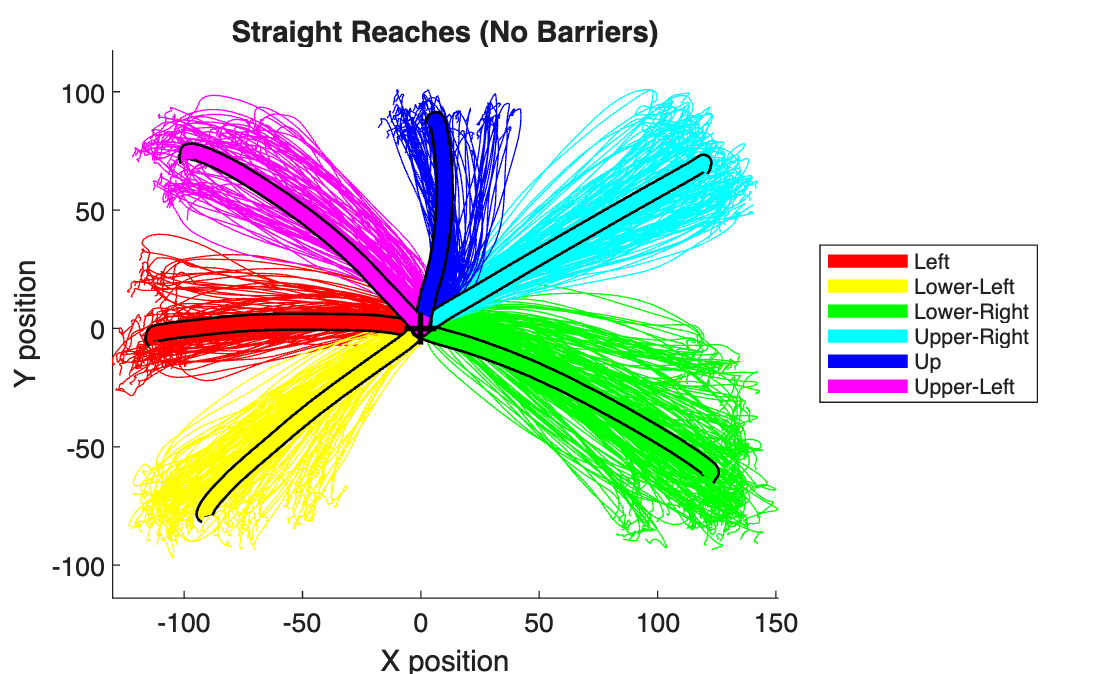

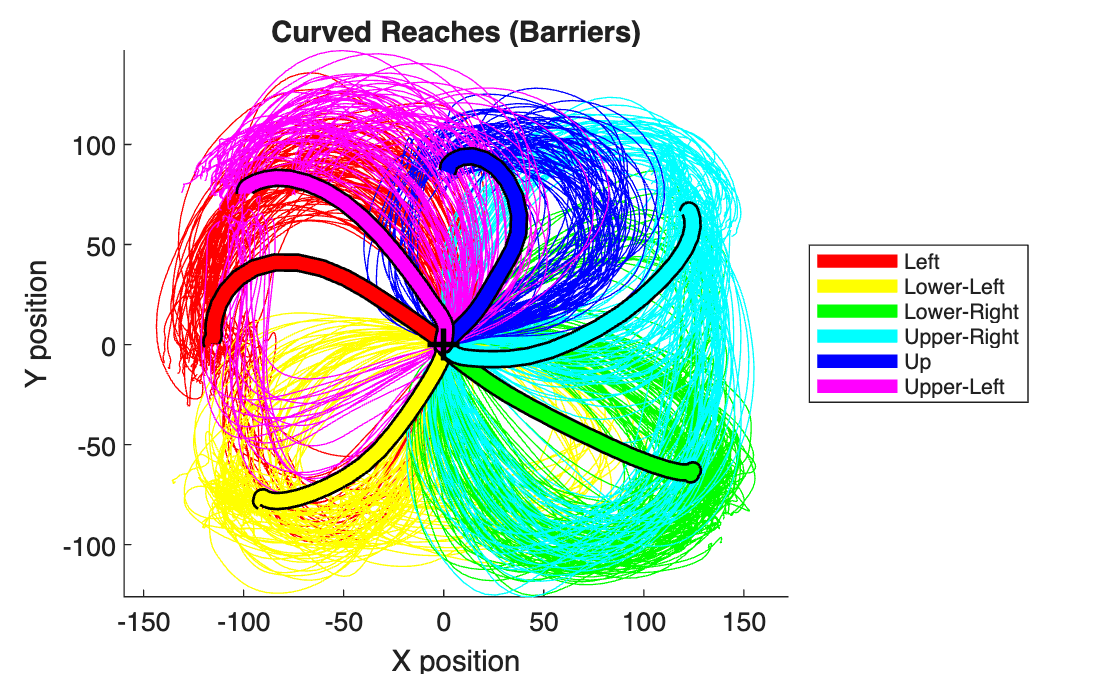

plotHandTrajectories(R);

- **Interpretation**

- This visualization plots the hand position of the monkey throughout the trial, divided by condition (curved vs. straight) and colored by direction. The thin lines represent individual trial trajectories, whereas the bold thick lines are the trial averaged means. There are several features of the data that are worth noting. First, the data supports our reach direction clustering as a relevant task feature, as the individual trajectories naturally cluster into 6 distinct directions. Second, the two conditions produce very different kinematic trajectories. The curved reaches are noticeably more variable, reflecting the need to avoid the obstacles. On the other hand, the no barriers condition produces relatively straight and radially organized paths to their targets.

- Note that the mean trajectories have been time normalized. So timing differences are smoothed over for the sake of visualization.

## Raster Plots

Neural: Raster plot for an example M1 neuron with trials sorted by reach direction and aligned to the movement onset

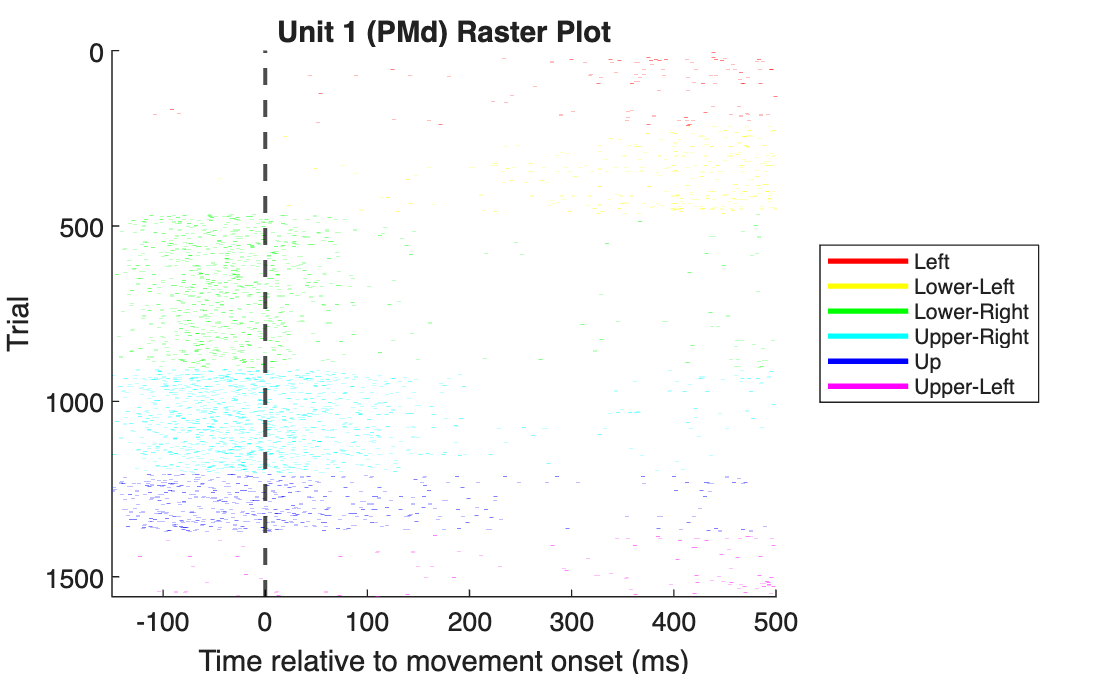

plotRaster(R, 1, 150, 500); % inputs in order: dataset, unit number, pre movement window(ms), post movement window(ms).

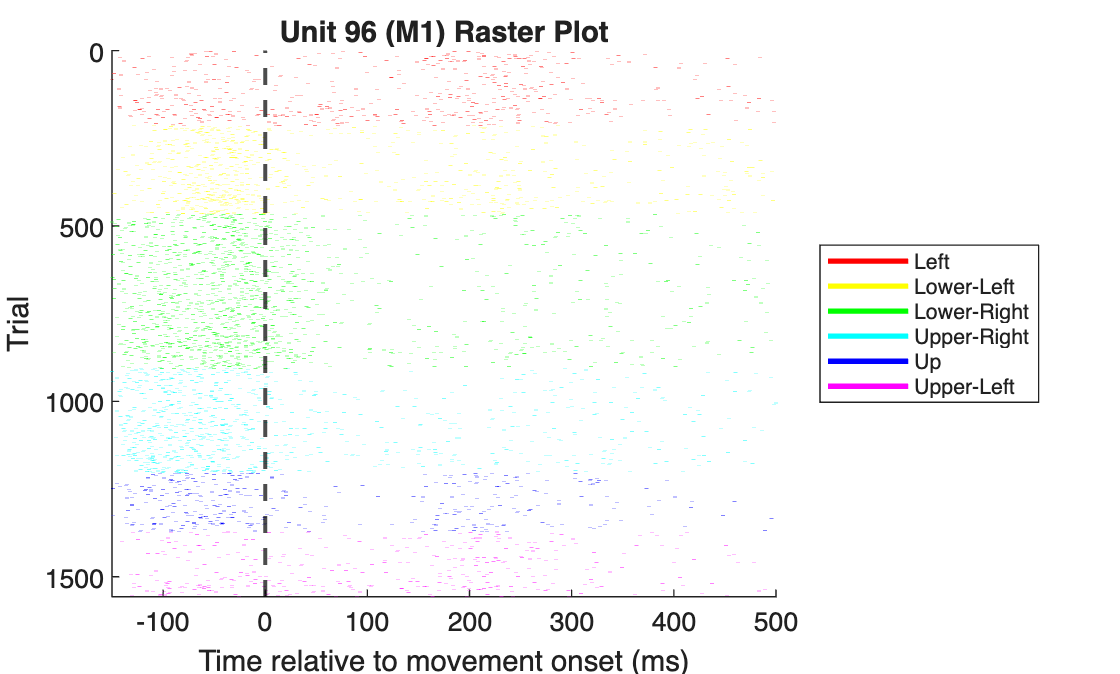

plotRaster(R, 96, 150, 500);

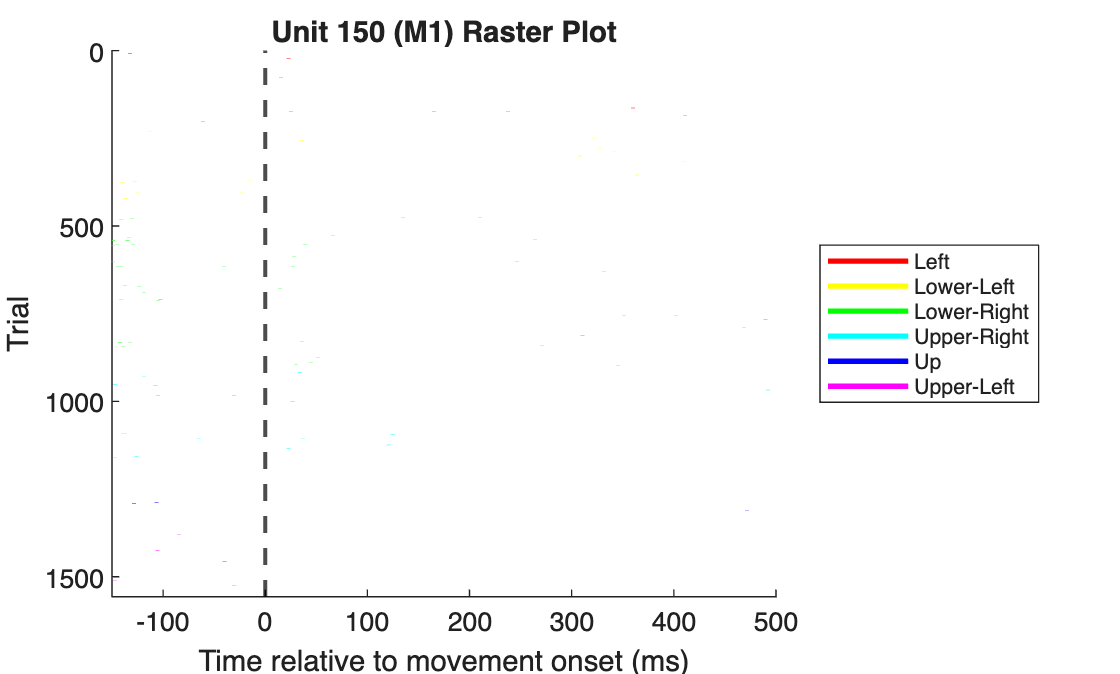

plotRaster(R, 150, 150, 500);

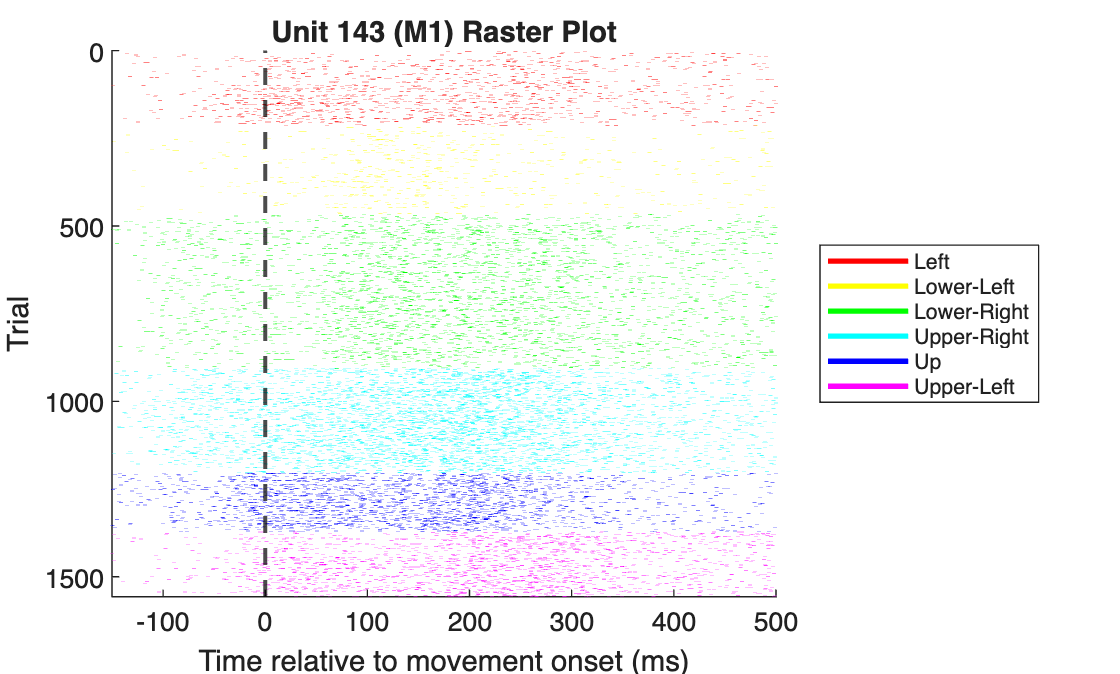

plotRaster(R, 143, 150, 500);

**Interpretation:**

- Here we've plotted several example raster plots of neural activity centered around movement onset during the task. This type of visualization allows us to characterize the neuron's directional tuning, amplitude of response, and temporal profile. We chose 4 neurons that show the heterogeneity of potential responses.

- Unit 1 responds predominately to reaches spanning lower right to up in the task. Notably, the peak response occurs before movement onset, which may be indicative of preparatory activity. The firing of this neuron seems to fade as the trial progresses.

- Unit 96 looks to have a much broader tuning profile, as it responds to nearly all reach directions, albeit a few more strongly. Similarly to neuron 1, firing seems to slow after movement onset for most of the directions, except for left/up, which has an additional response during movement.

-  Unit 150 is not tuned to any of the directions, only sparsely firing throughout the trials with no apparent structure.

- Unit 143 also shows a very broad tuning profile, but it has different temporal characteristics. Activity ramps during the delay period, but peaks and maintains throughout the movement epoch.

- This all goes to show the variability in response in both M1 and PMd, units in both regions show different firing rates, modulation depths, and tuning.

## Peri-Stimulus Time Histograms

Neural: PSTH for the same example M1 neuron averaged by reach direction condition and aligned to movement onset

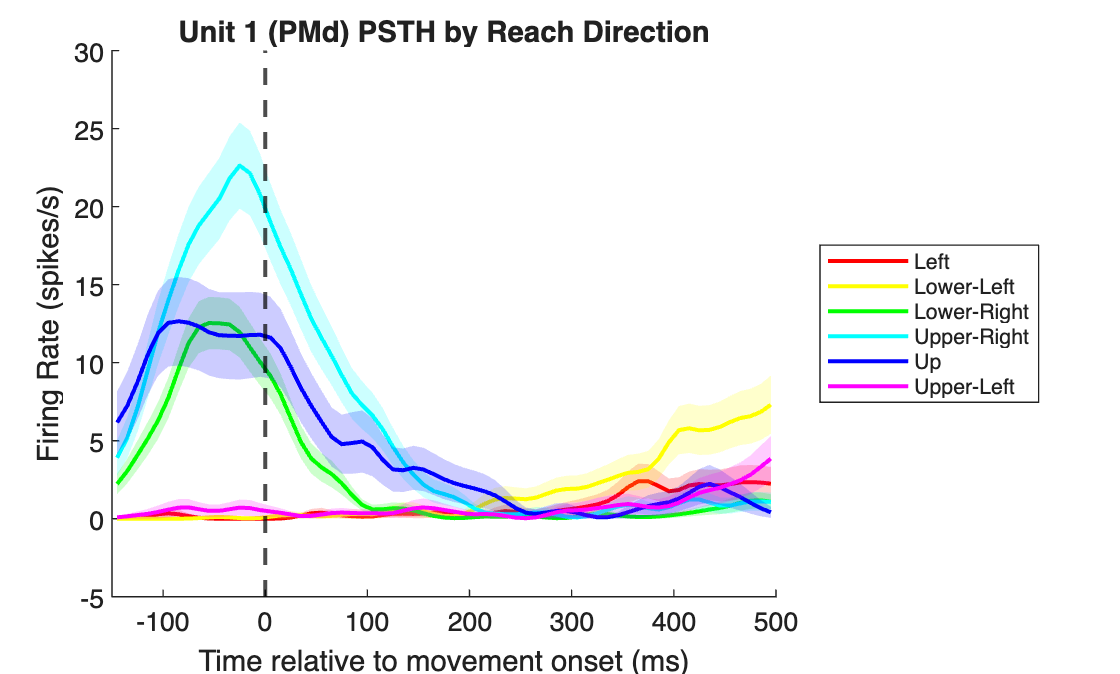

plotPSTH(R, 1, 150, 500, 10); % inputs in order: data set, unit number, pre movement window(ms), post movement window(ms), bin size(ms)

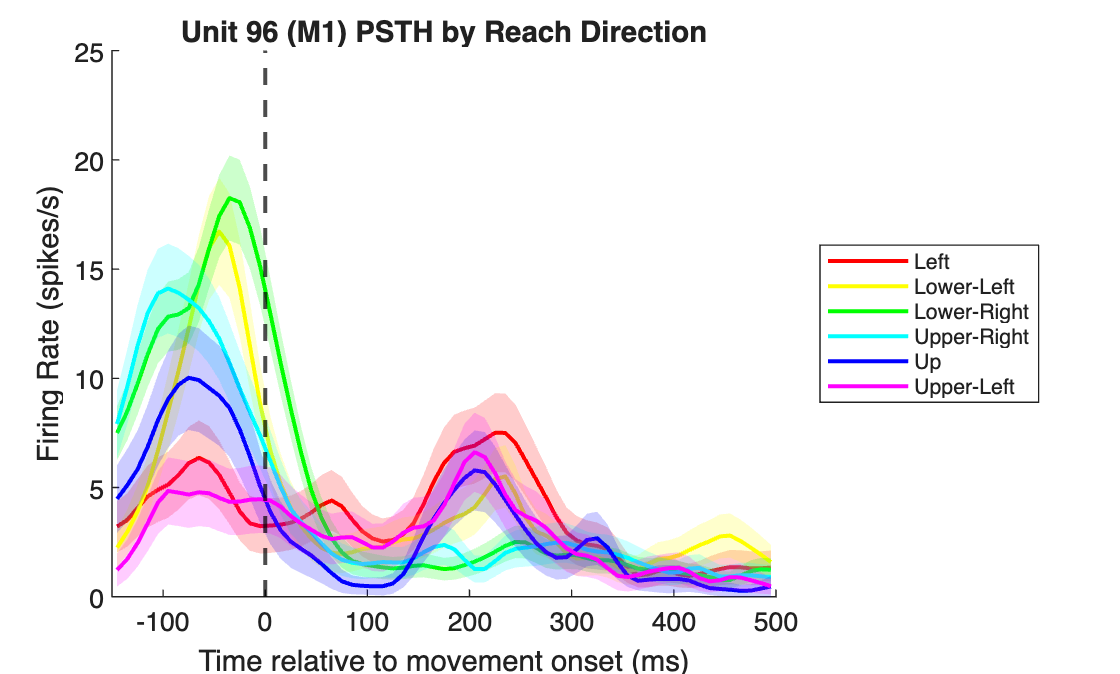

plotPSTH(R, 96, 150, 500, 10);

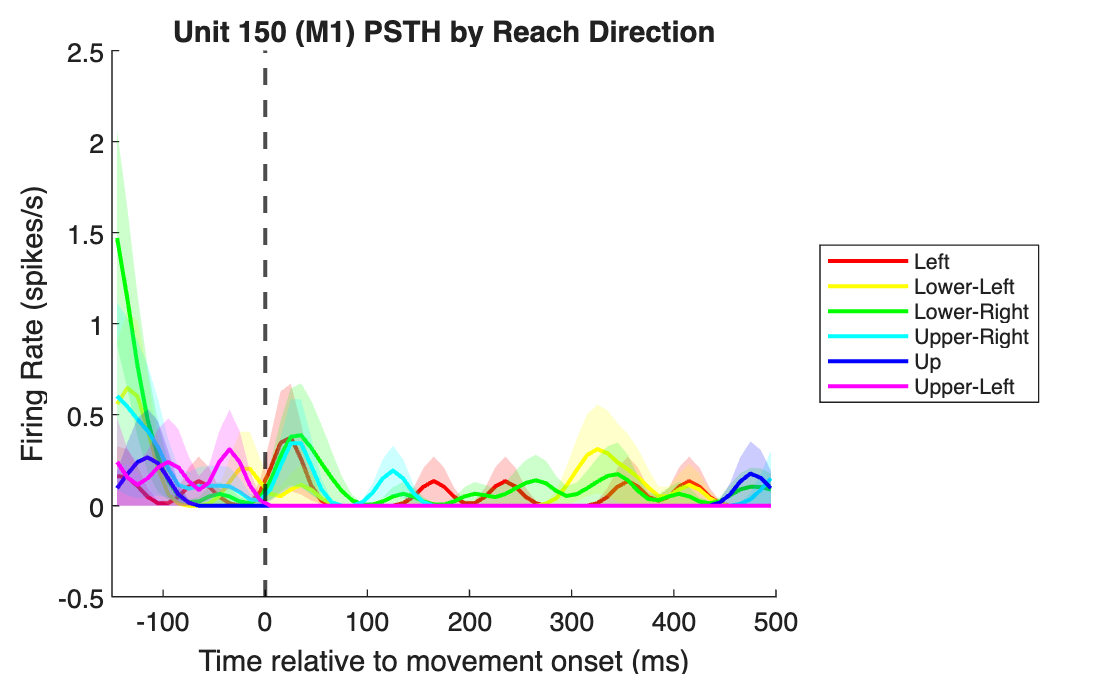

plotPSTH(R, 150, 150, 500, 10);

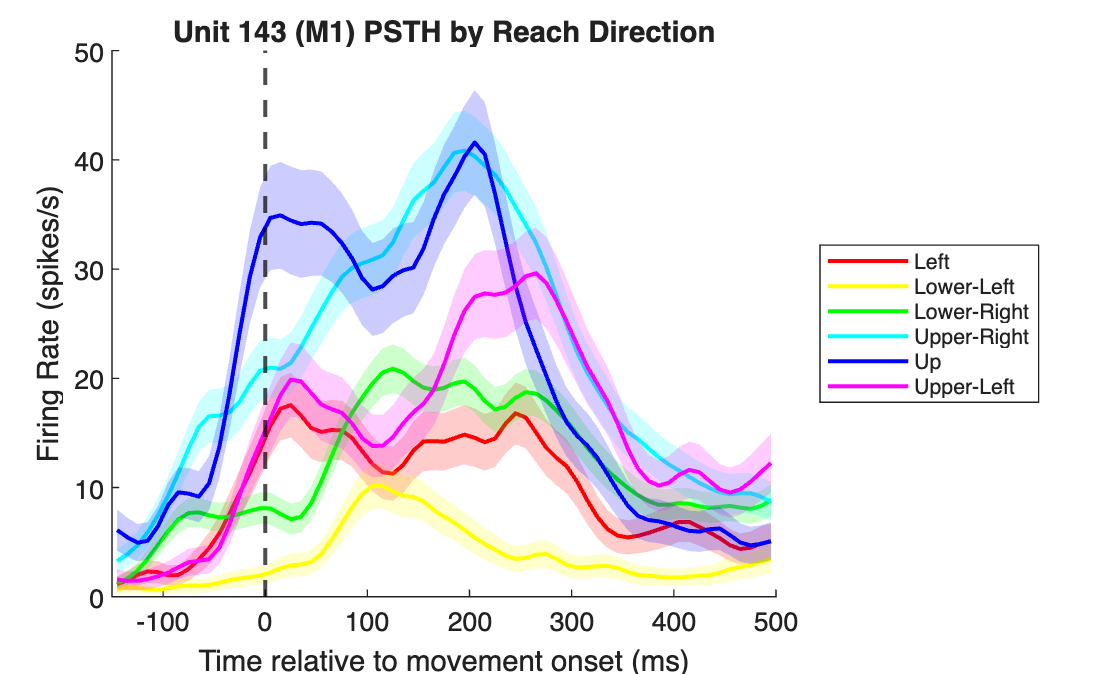

plotPSTH(R, 143, 150, 500, 10);

**Interpretation: **

- Here we have several Peri-Stimulus/Event Time Histograms for motor neurons aligned to movement onset. This is another type of neural data visualization that can show trends/responses across time as well as the preferred conditions where a neuron exhibits its optimal firing response.

- Neuron 1: Has clear directional tuning to up through lower right, peaking before movement onset and decaying throughout the movement epoch. 

- Neuron 96: Has relatively strong directional tuning to most directions, with a weaker response to left and upper left. Activity peaks before movement onset and decays at a much faster rate than previously seen with neuron 1. There does seem to be an additional response at 200 ms after movement onset, which could be representative of a movement parameter or something that occurred in the trial.

- Neuron 150: Shows no clear directional tuning for this neuron. It's firing rate is generally flat and noisy.

- Neuron 143: Has broad tuning to nearly all directions. Activity ramps up during the delay period but peaks later on in the movement period around 200 ms in.

- Again these visualizations display the heterogeneity of response found at the level of individual units, not all M1 units are exclusively active during the movement phase and not all PMd neurons during the delay phase. Neurons in both regions can be active during both phases of the task.

- In comparing the PSTHs and raster plots, it often can be easier to visualize the direction that elicits the highest firing response given how the data is represented.

## Tuning Curve Plot

Neural: Tuning curve plot for each neuron overlaid, with the mean in bold to show tuning across the population

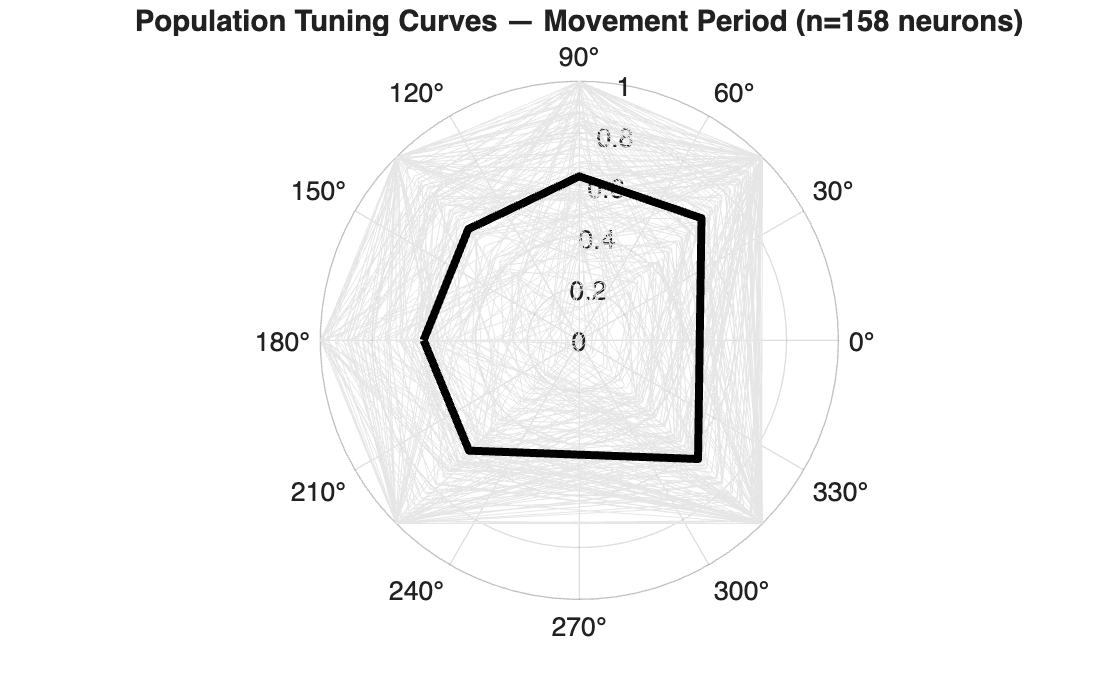

plotTuningCurve(R);

**Interpretation:**

- The population shows broad heterogeneity in response to all directions across both brain regions. It appears that individual neurons are tuned to all reach direction clusters, and it does not seem like one direction dominates. The population mean curve supports this as it is similarly uniform across the polar plot. This motivates population level analyses, where we can look at what the population encodes.

- The 6 vertices correspond to the 6 reach direction clusters we divided by. The connecting lines are thus linear interpolations between the groups.

## Neurometric Functions

- Traditional single-neuron analysis

- We will use an ROC based Ideal Observer Analysis to compute each M1 neuron’s discriminability between its preferred target location and each of the other targets as a function of angular distance from the preferred, producing a neurometric function per neuron. We will show the average discriminability curve across all neurons as well.

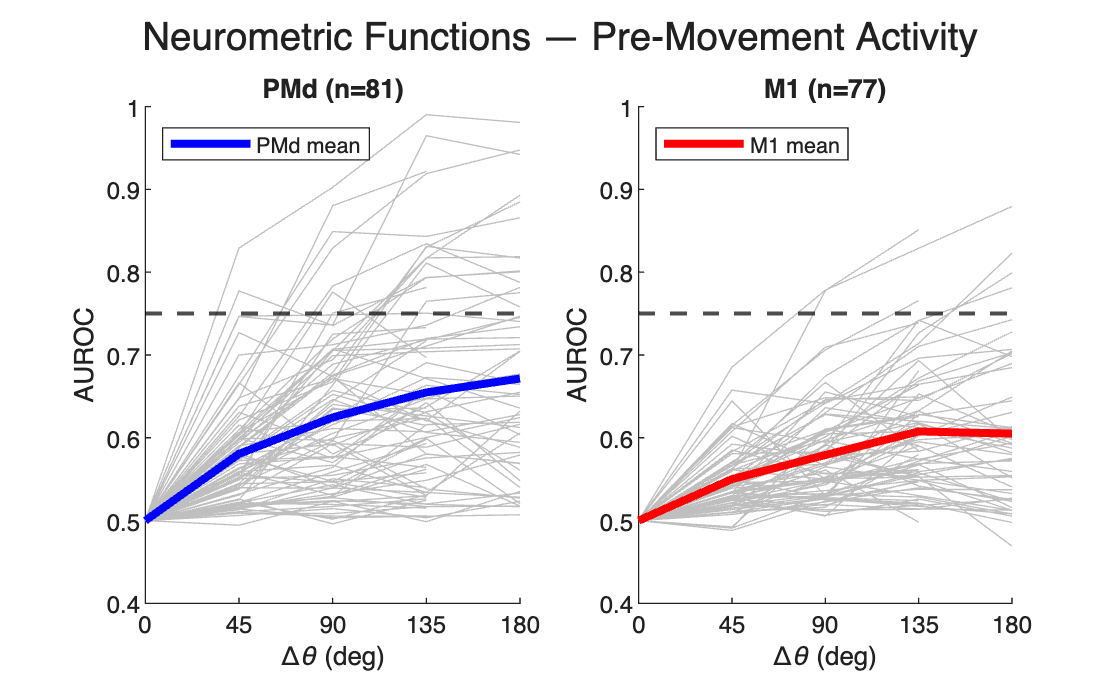

PMd: 18/81 neurons (22%) exceed AUROC 0.75 at any distance
M1:  6/77 neurons (8%) exceed AUROC 0.75 at any distance


plotNeurometricFunctions(R, 250);

- **Interpretation**

- Here we have neurometric functions for all 158 motor units, split by brain region, using an ROC ideal observer analysis during the delay period of the task. We plotted each individual neuron's discriminability as a function of angular distance from its preferred reach direction as a transparent gray line, and the average curve for the population as the blue and red lines. The question addressed with this analysis is how well individual neurons can discriminate between their preferred direction and all other directions, and whether that differs across brain region. The neurometric functions reveal that PMd shows greater directional discriminability than M1 units across all angular differences, peaking at around 0.67 at opposing directions, while M1 only peaks at about 0.60. Furthermore, approximately 22% of units in PMd cross our 0.75 threshold compared to only 8% in M1. 

- It's important to note, however, that there is a lot of heterogeneity across the population during preparatory activity. Both brain regions have neurons that are excellent discriminators, and many neurons that cluster around chance. The fact that the mean curve also never passes our threshold suggests that such task features may be better represented in population level activity

- This also reveals that while PMd may have more directional discriminability during the delay period, M1 is also able to discriminate. Thus, the functionality of these two brain regions overlap and can be thought of as a spectrum rather than a hard boundary in which PMd is exclusively motor planning and M1 is exclusively motor execution.

## Nonlinear Dimensionality Reduction:

- Clustering or nonlinear dimensionality reduction

- We will use t-SNE and UMAP on the M1 data and color their embeddings by reach conditions to determine whether both methods result in similar organization of neural states. We can follow up by correlating the pairwise distance matrices of both embeddings to compare their agreement.

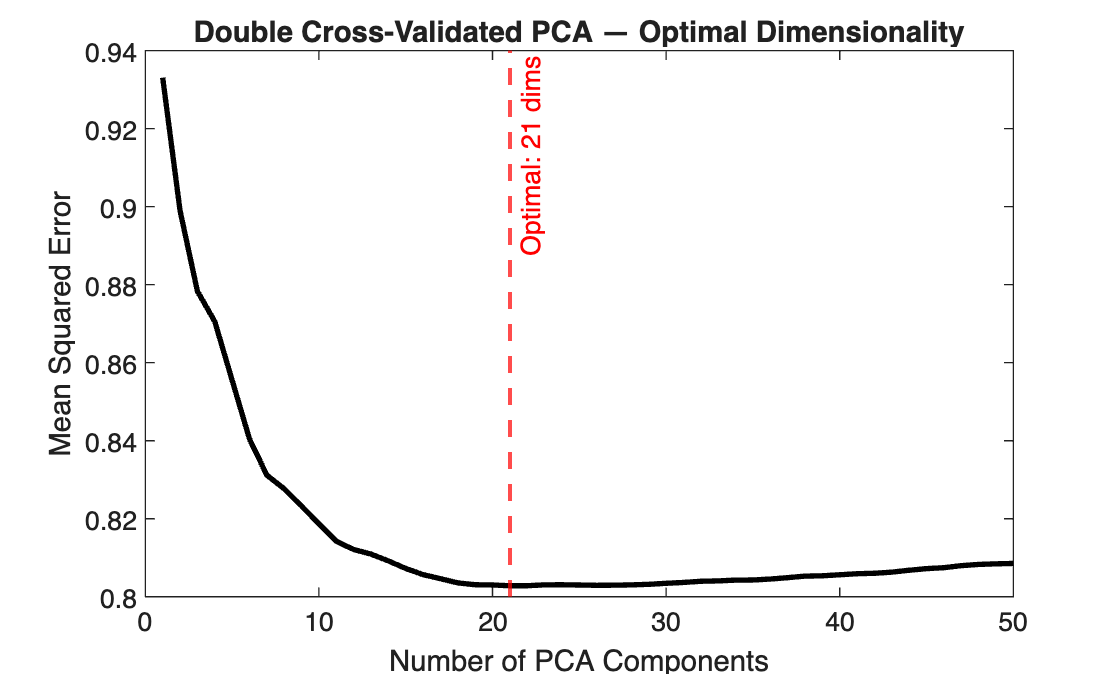

Optimal dimensionality: 21


[firingRateMatrix, conditionLabels] = buildFiringRateMatrix(R);
[optimalDims, pcaData] = crossValidatePCA(firingRateMatrix, 50);

- **Interpretation**

- We employed a double cross validation approach in which we split both the trials and neurons to find the optimal number of dimensions that explain the variance of our data. Upon sweeping to 50 dimensions, we found that approximately 21 dimensions minimized the mean squared error, which is the dimensionality we used in our nonlinear dimensionality reduction visualizations. This is done for the movement period of the trials. 

- This is a necessary step to prevent tears and twists and helps deal with the "curse of dimensionality." In such high dimension space, pairwise distances aren't reliable as nearly everything is equidistant. Running PCA on the data first, compresses it into meaningful dimensions.

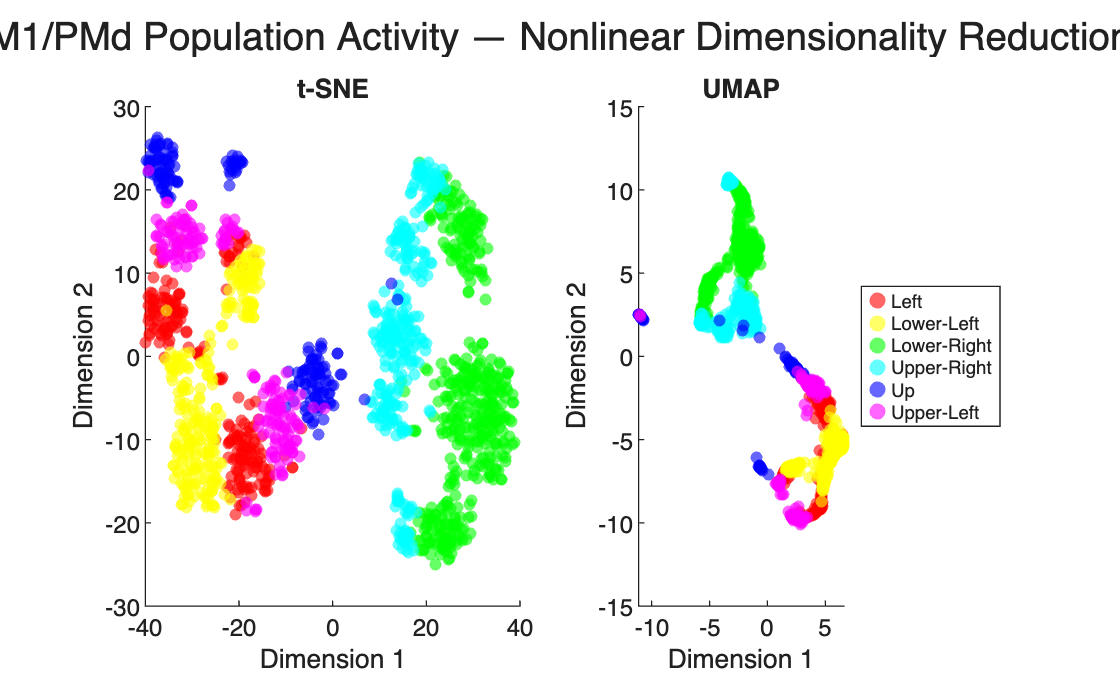

Pairwise distance matrix correlation (t-SNE vs UMAP): r = 0.804


% Plot
plotNLDimReduction(pcaData, conditionLabels);

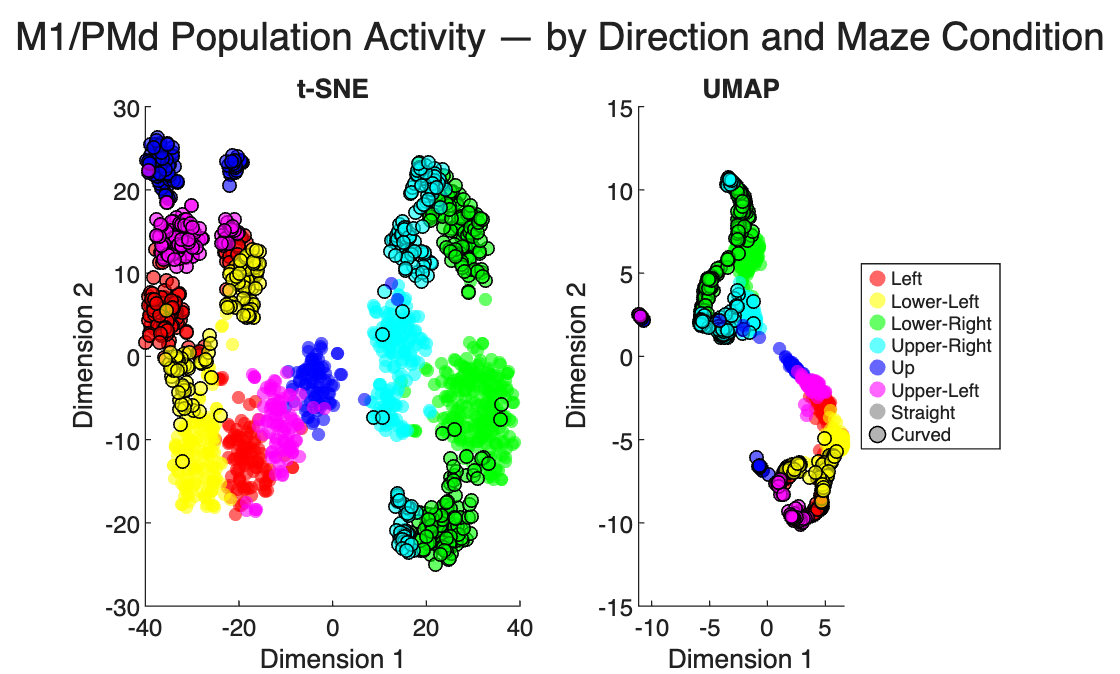

Pairwise distance matrix correlation (t-SNE vs UMAP, by-condition): r = 0.804
Straight trials: 788, Curved trials: 769


% Plot by Condition
isStraight = [R.mazeCategory] == 'noBarriers';
isStraight = isStraight(:);
[tSNEEmbedding, umapEmbedding] = plotNLDimReductionByCondition(pcaData, conditionLabels, isStraight);

- **Interpretation:**

- Both t-SNE and UMAP separate our defined clusters, confirming that direction is a relevant axis of variance during movement. Furthermore, adjacent directions do appear to cluster in similar spaces in both methods. However, it is important to note that the geometry of each embedding should be interpreted with caution. One reason for this is that target directions are not uniformly sampled around the circle and the number of trials per direction varies a sizable amount(168 - 440). Because nonlinear dimensionality reduction can be sensitive to local neighborhood densities, the geometry of the embeddings(size and shape) may partially reflect uneven sampling rather than real neural structure. 

- Splitting the visualization further by task condition(barrier vs no barrier) reveals that the type of reach is another feature organized in the low d manifold. This suggests that population activity also encodes reach type, something that may not be visible in individual neuron level analysis. 

- Additional analysis: We computed the pairwise distances for every pair of trials in the embedding and then correlated the two vectors, asking the question: for each pair of trials, do t-SNE and UMAP agree on how far they are. We got r = 0.804, which suggests that the two methods actually agree a fair amount in their visualizations.

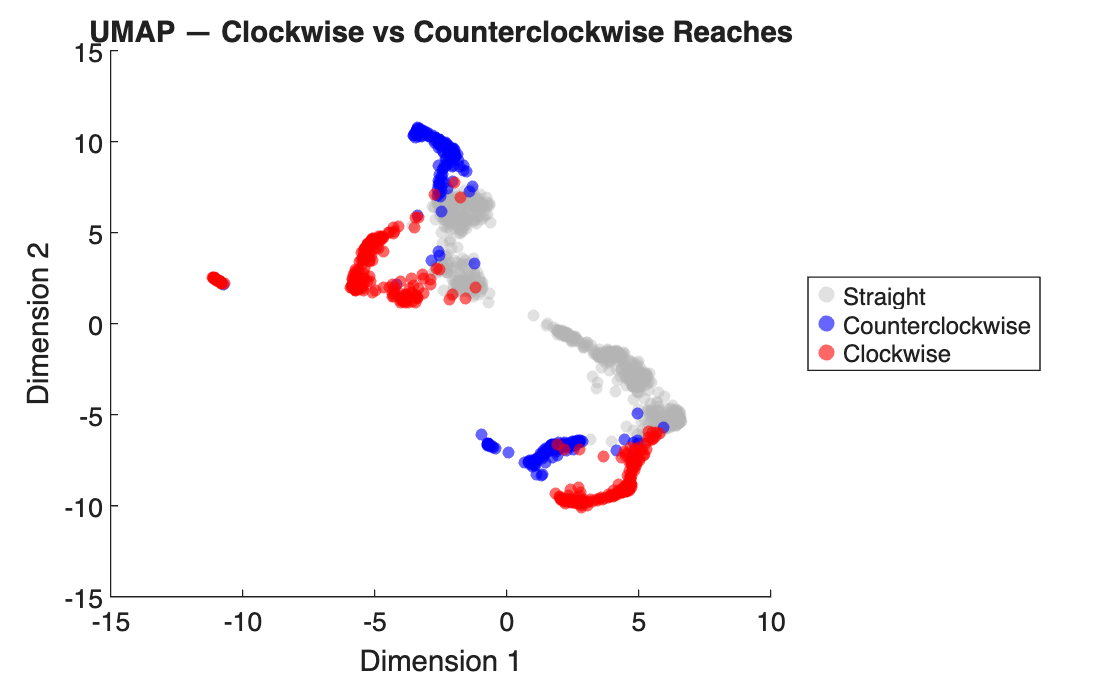

CW: 476, CCW: 293, Straight: 788


% Separate clockwise vs. counterclockwise
curveDir = getCurveDirection(R);
plotUMAPByCurve(umapEmbedding, curveDir);

**Interpretation:**

- Taking a look at whether or not the rings that emerged from the UMAP embedding were a result of counterclockwise vs clockwise reaches. We performed an additional visualization to separate the two. It appears that the rings are a product of curve direction as this feature too is well separable in the manifold. It then seems that the population activity is encoding another relevant behavioral feature in this low dimensional representation, which manifest as circular/curved patterns, similar to the movements themselves. 

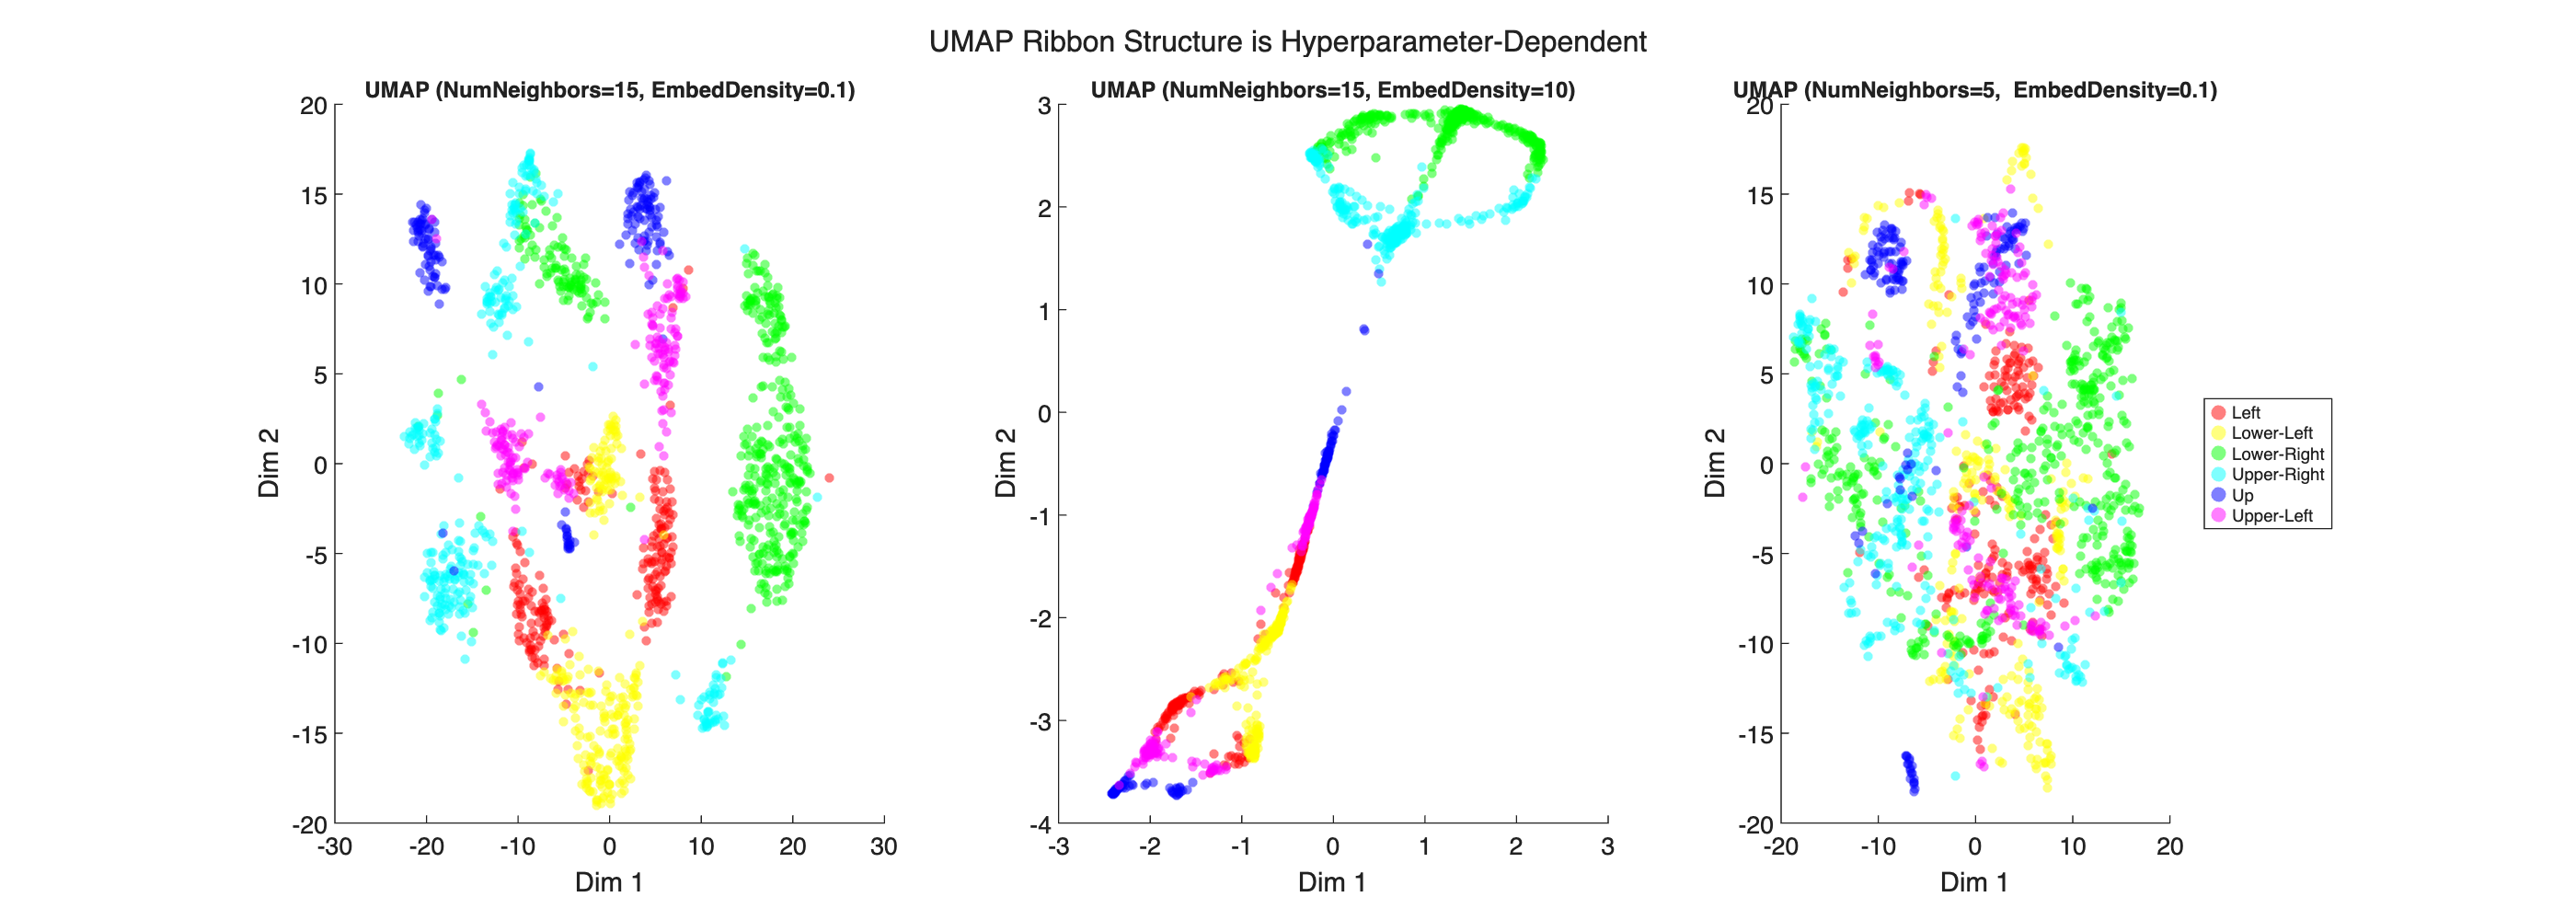

% Hyperparameter Examination

% UMAP
figure('Position', [100 100 1400 500]);

rng(1);
umap1 = umap(pcaData, 'NumNeighbors', 15, 'EmbeddingDensity', 0.1);
rng(1);
umap2 = umap(pcaData, 'NumNeighbors', 15, 'EmbeddingDensity', 10);
rng(1);
umap3 = umap(pcaData, 'NumNeighbors', 5,  'EmbeddingDensity', 0.1);

umapEmbeddings = {umap1, umap2, umap3};
umapTitles = {'UMAP (NumNeighbors=15, EmbedDensity=0.1)', ...
    'UMAP (NumNeighbors=15, EmbedDensity=10)', ...
    'UMAP (NumNeighbors=5,  EmbedDensity=0.1)'};

colors = hsv(6);
dirLabels = {'Left','Lower-Left','Lower-Right','Upper-Right','Up','Upper-Left'};
uniqueConditions = unique(conditionLabels);

for e = 1:3
    subplot(1, 3, e);
    hold on;
    for c = 1:6
        mask = conditionLabels == uniqueConditions(c);
        scatter(umapEmbeddings{e}(mask,1), umapEmbeddings{e}(mask,2), ...
            15, colors(c,:), 'filled', 'MarkerFaceAlpha', 0.5, ...
            'DisplayName', dirLabels{c});
    end
    title(umapTitles{e}, 'FontSize', 9);
    xlabel('Dim 1');
    ylabel('Dim 2');
    if e == 3
        legend('Location', 'eastoutside', 'FontSize', 7);
    end
    hold off;
end
sgtitle('UMAP Ribbon Structure is Hyperparameter-Dependent', 'FontSize', 12);

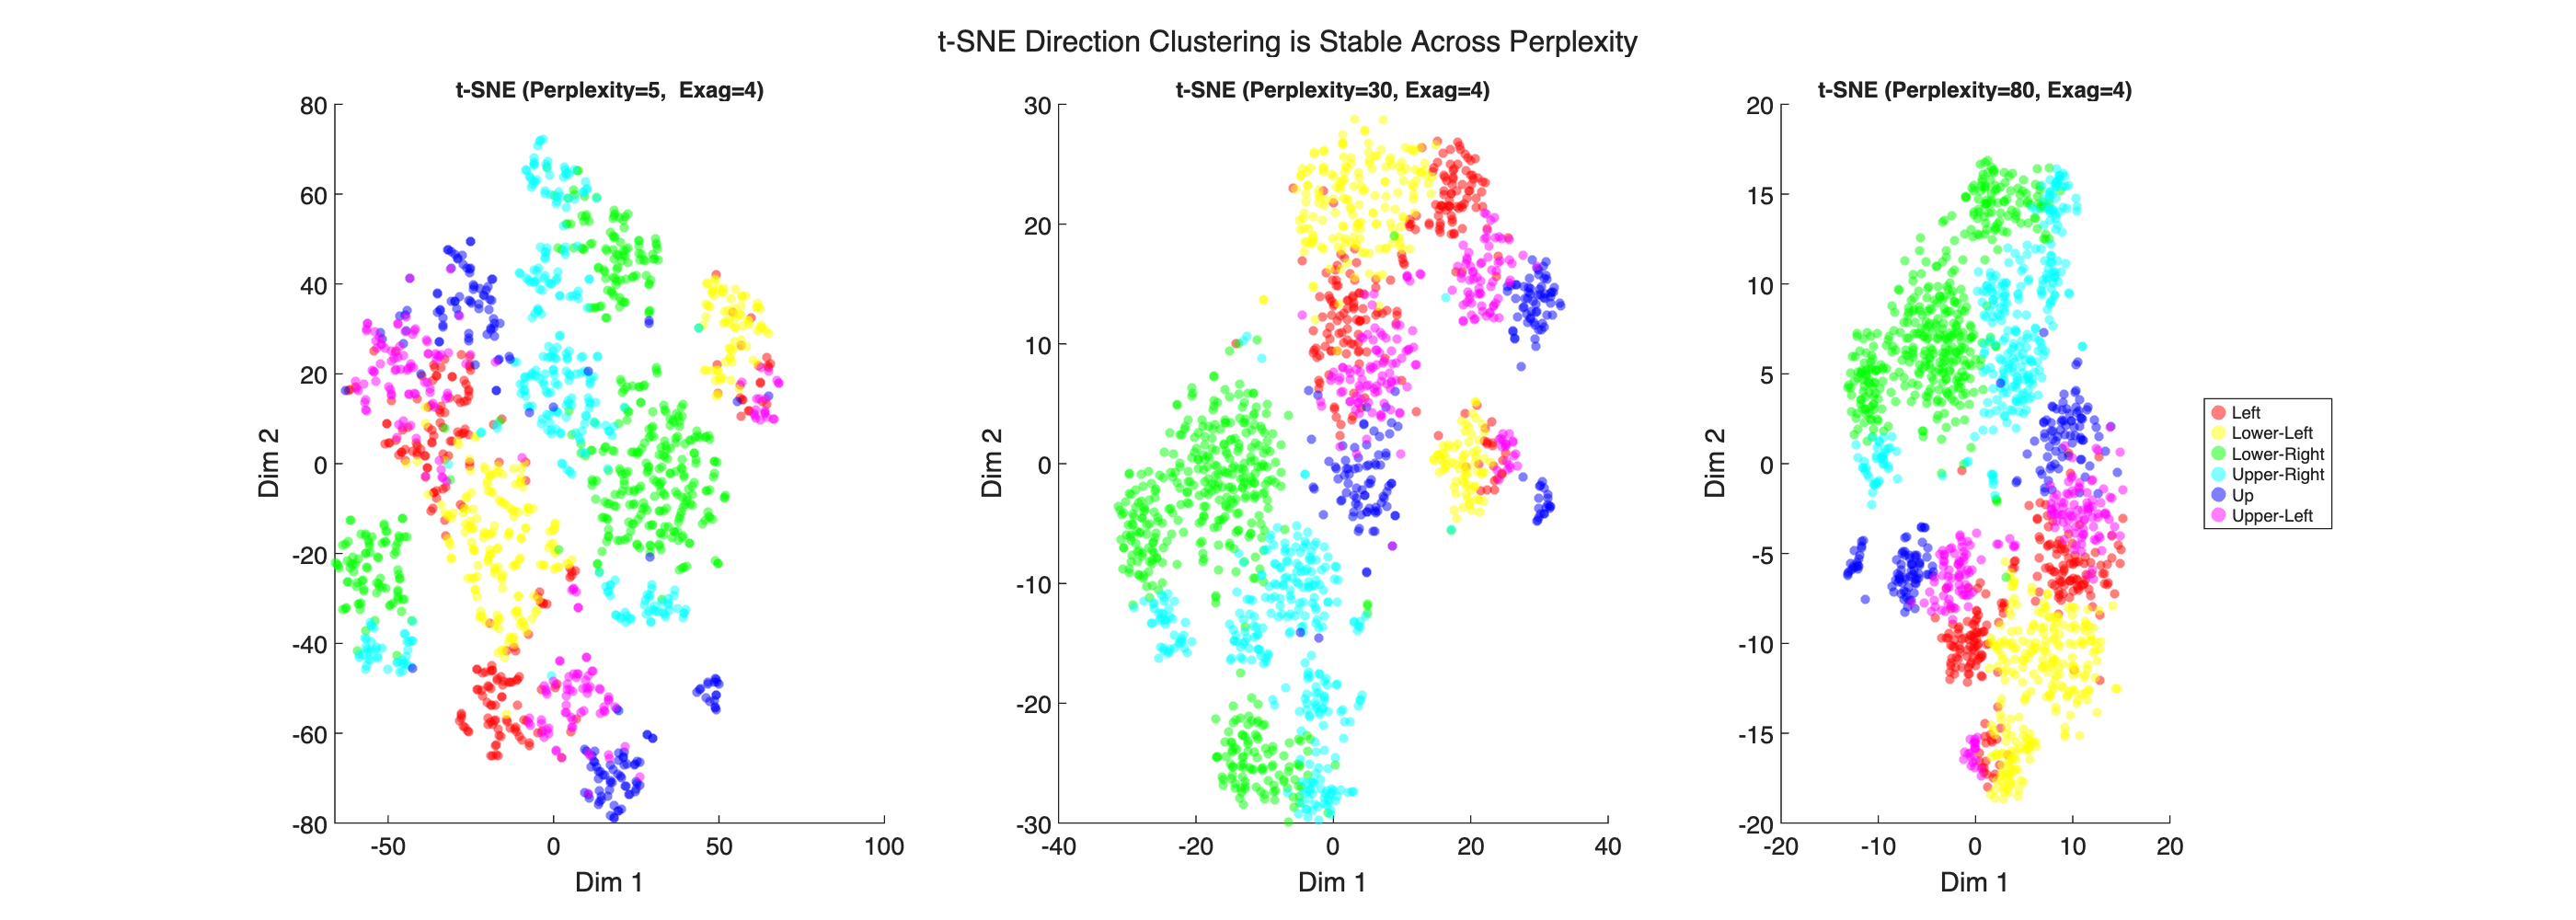



% t-SNE
figure('Position', [100 100 1400 500]);

rng(1);
tsne1 = tsne(pcaData, 'NumDimensions', 2, 'Perplexity', 5,  'Standardize', true, 'Exaggeration', 4);
rng(1);
tsne2 = tsne(pcaData, 'NumDimensions', 2, 'Perplexity', 30, 'Standardize', true, 'Exaggeration', 4);
rng(1);
tsne3 = tsne(pcaData, 'NumDimensions', 2, 'Perplexity', 80, 'Standardize', true, 'Exaggeration', 4);

tsneEmbeddings = {tsne1, tsne2, tsne3};
tsneTitles = {'t-SNE (Perplexity=5,  Exag=4)', ...
    't-SNE (Perplexity=30, Exag=4)', ...
    't-SNE (Perplexity=80, Exag=4)'};

for e = 1:3
    subplot(1, 3, e);
    hold on;
    for c = 1:6
        mask = conditionLabels == uniqueConditions(c);
        scatter(tsneEmbeddings{e}(mask,1), tsneEmbeddings{e}(mask,2), ...
            15, colors(c,:), 'filled', 'MarkerFaceAlpha', 0.5, ...
            'DisplayName', dirLabels{c});
    end
    title(tsneTitles{e}, 'FontSize', 9);
    xlabel('Dim 1');
    ylabel('Dim 2');
    if e == 3
        legend('Location', 'eastoutside', 'FontSize', 7);
    end
    hold off;
end
sgtitle('t-SNE Direction Clustering is Stable Across Perplexity', 'FontSize', 12);

- **Interpretation**

- To test how dependent the global structure of these embeddings are on the hyperparameters, we varied perplexity for t-SNE and NumNeighbors and embedding density for UMAP. For t-SNE, perplexity controls the number of neighbors each point considers, a lower perplexity focuses on local structure, whereas a higher perplexity incorporates a broader neighborhood. Across the 3 perplexity values we tested, t-SNE produces similar looking embeddings, defined by discrete and well separated direction clusters.

- For UMAP, the hyperparameters we adjusted were NumNeighbors, which is similar to perplexity and embedding density, which controls how tight points are packed in the manifold. With the default settings, we saw the embedding form continuous thin structures. Increasing embedding density further compacts the visualization further. On the other hand, decreasing the number of neighbors to 5 produces a more discrete clustering as we saw in t-SNE. This reveals that the shapes we saw earlier for UMAP were largely dependent on the hyperparameters, not necessarily features of our data.

- Taking this together, the directional cluster remains consistent across both methods and the various parameters we tested. Trials that were towards the same reach direction tended to group together. However, the specific differences in geometry should be treated with caution, as you can achieve relatively similar arrangements in both methods.

## Decoder: Ridge Regression vs. Random Forest

- Decoders

- We will decode position/velocity over time from M1 neural data using 1) ridge regression and 2) random forest regression, comparing cross validated performance and their resulting reach trajectories.

decoderModel = trainDecoder(R, 5);

Ridge: best lambda: 494.1713 , CV R²: Vx=0.681, Vy=0.470
Random Forest — R²: Vx=0.685, Vy=0.488


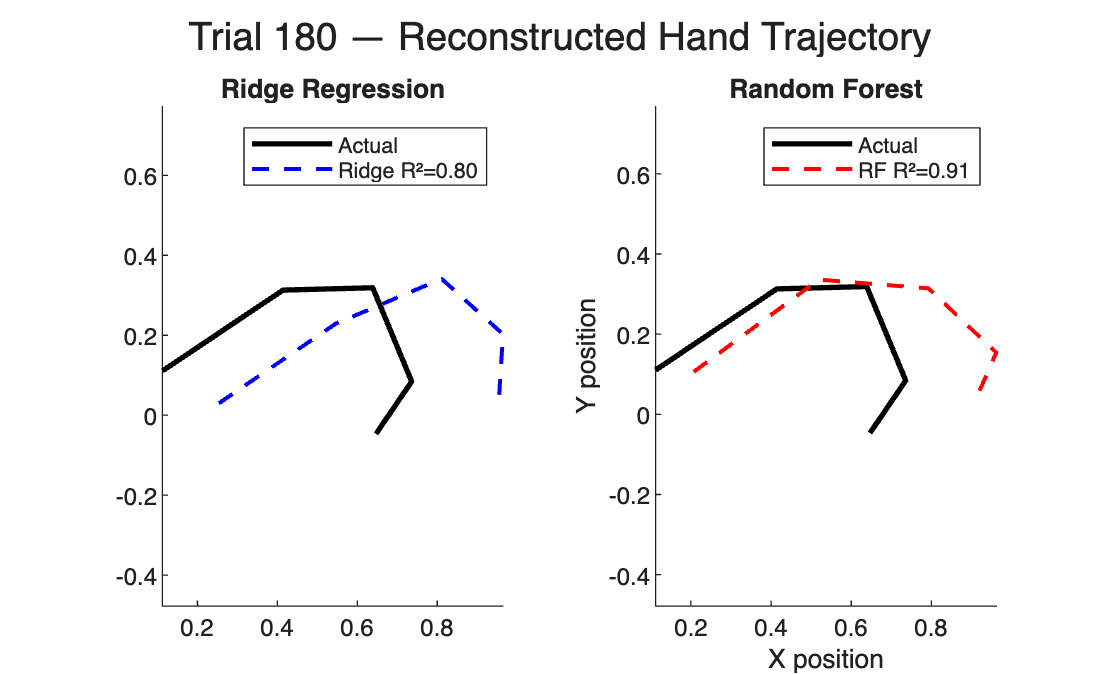

plotDecodedTrajectory(decoderModel, R, 180);

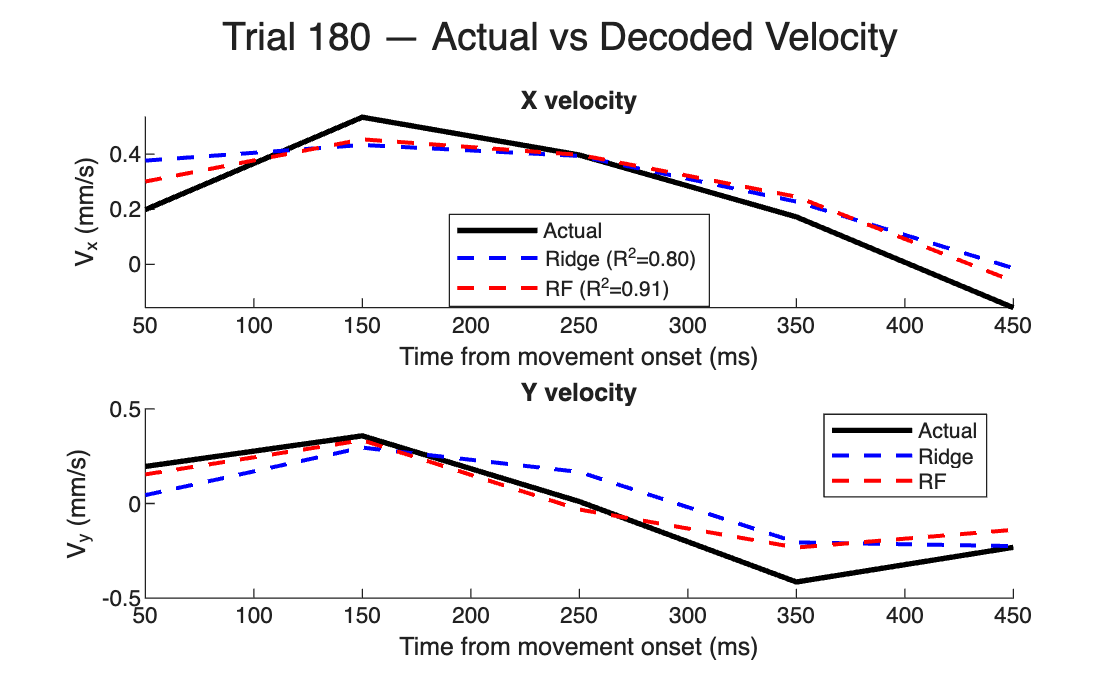

plotDecodedVelocity(decoderModel, R, 180);

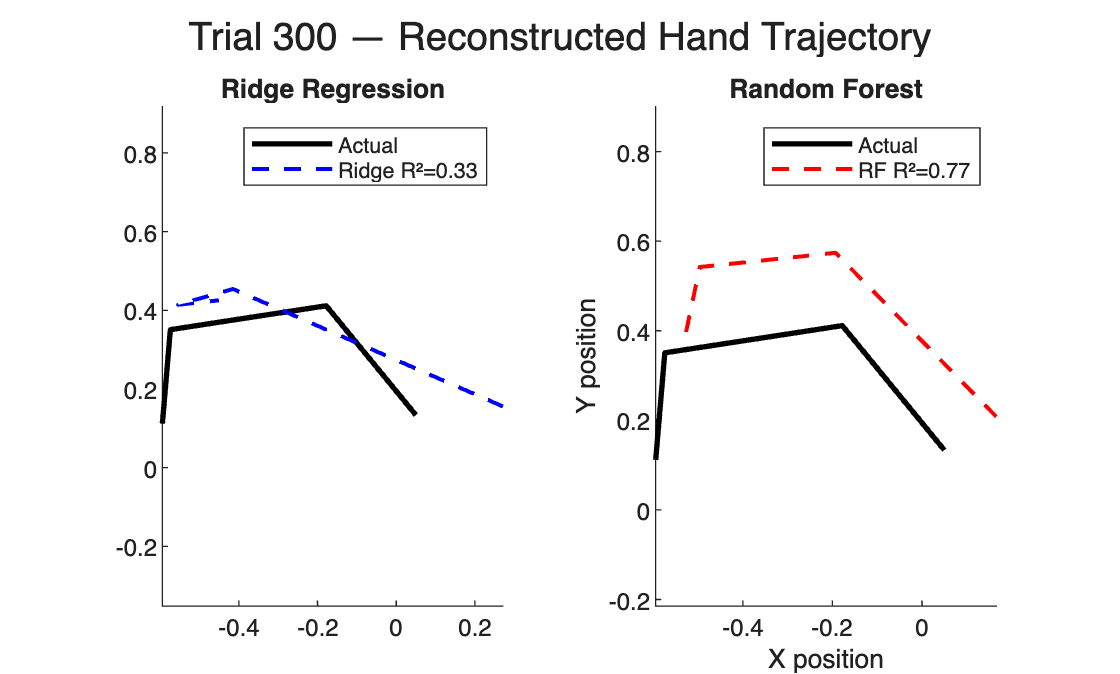

plotDecodedTrajectory(decoderModel, R, 300);

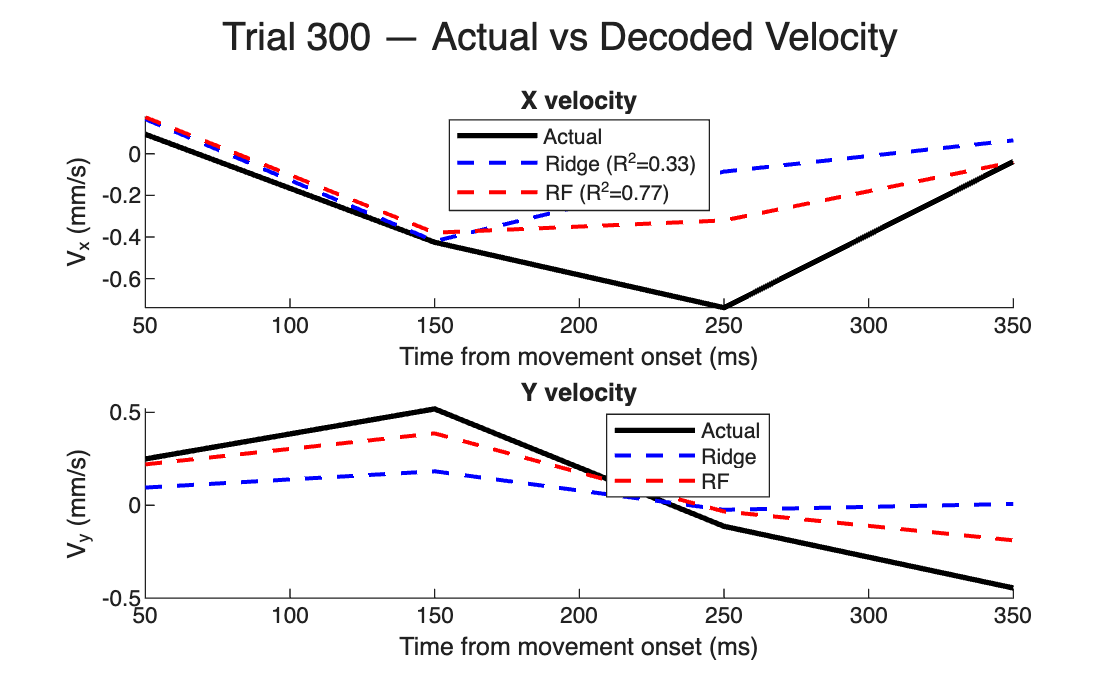

plotDecodedVelocity(decoderModel, R, 300)

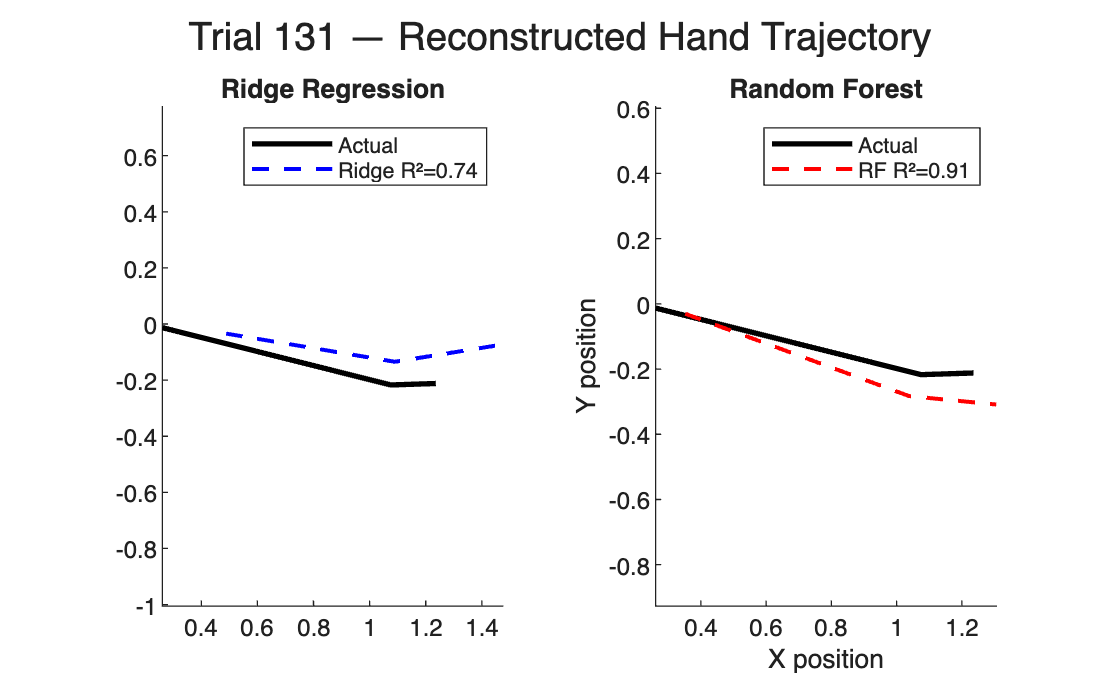

plotDecodedTrajectory(decoderModel, R, 131);

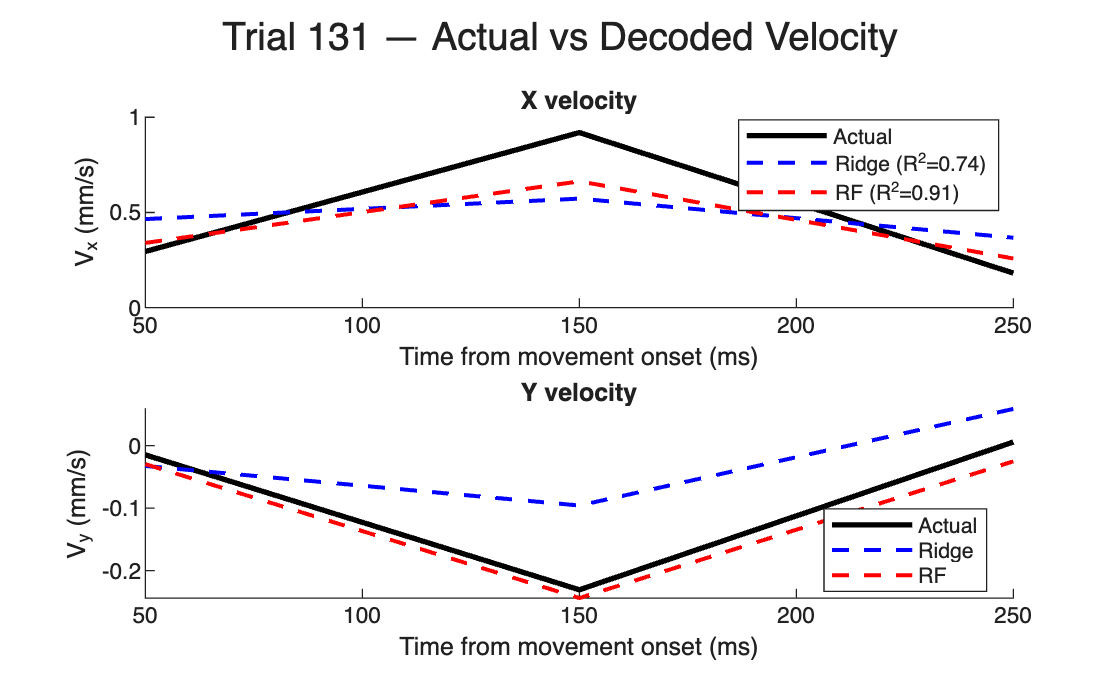

plotDecodedVelocity(decoderModel, R, 131);

- **Interpretation**

- It appears that the nonlinear decoder(random forest) and linear decoder(ridge regression) perform similarly well, as their cross validated R^2's are nearly identical. This lack of major difference seems to suggest that the relationship between firing rates and hand velocity is approximately linear. 

- The difference between aggregate performance is small enough that it does not provide strong evidence of a real nonlinear relationship. On the individual trials, random forest does seem to reconstruct trajectories more faithfully, but given that we only plotted 3 trials, this is more likely just trial to trial variability. 

- There does seem to be a tradeoff. A linear regression, like ridge regression, is more interpretable than the random forest approach, which is sort of like a black box. Random forest may perform better in some cases, but it's difficult to ask questions of. With a linear regression, we can directly ask what neurons contribute and how much, something that's important when we want to understand the motor cortex not just predict movement.

## Hand Trajectory Function

function plotHandTrajectories(R)
% Plot hand trajectories split by maze category
% (straight vs curved) and colored by reach direction.
% Individual trials shown as thin lines, means are the bold lines.
% All trajectories centered at movement onset position. Input is the maze
% data struc array.

% Get Direction Targets
targetXY = reshape([R.targetXY], 2, [])';
angles = atan2d(targetXY(:,2), targetXY(:,1));
angleGroups = round(angles / 45) * 45;
angleGroups(angleGroups == 180) = -180;
angleGroups(angleGroups == 0 & angles < 5)  = -45;   
angleGroups(angleGroups == 0 & angles >= 5) = 45;
uniqueGroups = unique(angleGroups);
nGroups = length(uniqueGroups);

dirLabels = {'Left', 'Lower-Left', 'Lower-Right', 'Upper-Right', 'Up', 'Upper-Left'};
colors = hsv(nGroups);

% Split by maze category
straightMask = [R.mazeCategory] == 'noBarriers';
curvedMask   = [R.mazeCategory] == 'barriers';
categoryMasks = {straightMask, curvedMask};
categoryNames = {'Straight Reaches (No Barriers)', 'Curved Reaches (Barriers)'};

for c = 1:2
    figure;
    hold on;

    meanXAll = cell(nGroups, 1);
    meanYAll = cell(nGroups, 1);

    for g = 1:nGroups
        groupMask = angleGroups == uniqueGroups(g);
        trialIdx  = find(groupMask & categoryMasks{c}');

        if isempty(trialIdx)
            continue
        end

        allX = {};
        allY = {};

        for tr = 1:length(trialIdx)
            trIdx     = trialIdx(tr);
            handX     = R(trIdx).HAND.X;
            handY     = R(trIdx).HAND.Y;
            handTimes = R(trIdx).HAND.times - R(trIdx).moveOnsetTime;

            % Center at movement onset position
            [~, onsetIdx] = min(abs(handTimes));
            handX = handX - handX(onsetIdx);
            handY = handY - handY(onsetIdx);

            % Plot individual trial
            h = plot(handX, handY, 'Color', colors(g,:), ...
                'LineWidth', 0.5, 'HandleVisibility', 'off');
            h.Color(4) = 0.05;

            allX{end+1} = handX;
            allY{end+1} = handY;
        end

        % Calculate mean
        nPoints = 100;
        meanX   = zeros(length(allX), nPoints);
        meanY   = zeros(length(allY), nPoints);

        for tr = 1:length(allX)
            tNorm        = linspace(0, 1, length(allX{tr}));
            tInterp      = linspace(0, 1, nPoints);
            meanX(tr, :) = interp1(tNorm, allX{tr}, tInterp);
            meanY(tr, :) = interp1(tNorm, allY{tr}, tInterp);
        end

        meanXAll{g} = mean(meanX, 1);
        meanYAll{g} = mean(meanY, 1);
    end

    % Plot means
    for g = 1:nGroups
        if ~isempty(meanXAll{g})
            plot(meanXAll{g}, meanYAll{g}, 'k-', 'LineWidth', 7, ...
                'HandleVisibility', 'off');
            plot(meanXAll{g}, meanYAll{g}, 'Color', colors(g,:), ...
                'LineWidth', 5, 'DisplayName', dirLabels{g});
        end
    end

    % Movement onset marker
    plot(0, 0, 'k+', 'MarkerSize', 12, 'LineWidth', 2, 'HandleVisibility', 'off');

    xlabel('X position');
    ylabel('Y position');
    title(categoryNames{c});
    legend('Location', 'eastoutside', 'FontSize', 8);
    axis equal;
    hold off;
end
end

## Raster Plot Function

function plotRaster(R, unitNum, preMovMs, postMovMs)
% Plot a raster for a single motor unit aligned to movement onset,
% with trials sorted and colored by reach direction group. Inputs include:
% maze data set, unit number, pre and post movement windows.

% Get Direction Targets
targetXY = reshape([R.targetXY], 2, [])';
angles = atan2d(targetXY(:,2), targetXY(:,1));
angleGroups = round(angles / 45) * 45;
angleGroups(angleGroups == 180) = -180;
angleGroups(angleGroups == 0 & angles < 5)  = -45;   
angleGroups(angleGroups == 0 & angles >= 5) = 45;
uniqueGroups = unique(angleGroups);
nGroups = length(uniqueGroups);

dirLabels = {'Left', 'Lower-Left', 'Lower-Right', 'Upper-Right', 'Up', 'Upper-Left'};
colors = hsv(nGroups);

% Brain area
arrayLabel = R(1).arrays{R(1).whichArray(unitNum)};

figure;
hold on;

trialOffset = 0;

for g = 1:nGroups
    groupMask = angleGroups == uniqueGroups(g);
    groupTrials = find(groupMask);

    % Dummy line for legend
    plot(NaN, NaN, 'Color', colors(g,:), 'LineWidth', 2, ...
        'DisplayName', dirLabels{g});

    for tr = 1:length(groupTrials)
        trIdx = groupTrials(tr);

        % Align spike times to movement onset
        spks = R(trIdx).unit(unitNum).spikeTimes;
        moveOnset = R(trIdx).moveOnsetTime;
        alignedSpks = spks - moveOnset;

        % Window
        windowMask = alignedSpks >= -preMovMs & alignedSpks <= postMovMs;
        alignedSpks = alignedSpks(windowMask);

        if isempty(alignedSpks)
            continue
        end

        % Plot spike ticks
        y1 = trialOffset + tr;
        y2 = y1 + 1;
        spksRep = repmat(alignedSpks', [2 1]);
        ypos = repmat([y1; y2], [1 length(alignedSpks)]);
        plot(spksRep, ypos, 'Color', colors(g,:), ...
            'LineWidth', 1.5, 'HandleVisibility', 'off');
    end

    trialOffset = trialOffset + length(groupTrials);
end

% Movement onset line
xline(0, 'k--', 'LineWidth', 1.5, 'HandleVisibility', 'off');

set(gca, 'YDir', 'reverse', 'YLim', [0 trialOffset]);
xlabel('Time relative to movement onset (ms)');
ylabel('Trial');
xlim([-preMovMs, postMovMs]);
title(sprintf('Unit %d (%s) Raster Plot', unitNum, arrayLabel));
legend('Location', 'eastoutside', 'FontSize', 8);
hold off;
end

## PSTH Function

function plotPSTH(R, unitNum, preMovMs, postMovMs, binSizeMs)
% Plot a PSTH for a motor unit aligned to movement onset,
% averaged by reach direction group with SEM error bounds. Inputs include:
% maze data set, unit to plot, ms before movement onset, ms after movement
% onset, and bin size.

% Get Direction Targets
targetXY = reshape([R.targetXY], 2, [])';
angles = atan2d(targetXY(:,2), targetXY(:,1));
angleGroups = round(angles / 45) * 45;
angleGroups(angleGroups == 180) = -180;
angleGroups(angleGroups == 0 & angles < 5)  = -45;   
angleGroups(angleGroups == 0 & angles >= 5) = 45;
uniqueGroups = unique(angleGroups);
nGroups = length(uniqueGroups);

dirLabels = {'Left', 'Lower-Left', 'Lower-Right', 'Upper-Right', 'Up', 'Upper-Left'};
colors = hsv(nGroups);

% Time axis
binEdges = -preMovMs : binSizeMs : postMovMs;
binCenters = binEdges(1:end-1) + binSizeMs/2;
nBins = length(binCenters);

% Brain area for this unit
arrayLabel = R(1).arrays{R(1).whichArray(unitNum)};

figure;
hold on;

for g = 1:nGroups
    % Direction group trials
    groupMask = angleGroups == uniqueGroups(g);
    groupTrials = find(groupMask);
    nTrials = length(groupTrials);

    % Preallocate Matrix
    spikeCounts = zeros(nTrials, nBins);

    for tr = 1:nTrials
        trIdx = groupTrials(tr);

        % Align spike times to movement onset
        spks = R(trIdx).unit(unitNum).spikeTimes;
        moveOnset = R(trIdx).moveOnsetTime;
        alignedSpks = spks - moveOnset;

        % Bin spikes
        spikeCounts(tr, :) = histcounts(alignedSpks, binEdges);
    end

    % Convert to firing rate in spikes/s
    firingRate = spikeCounts / (binSizeMs / 1000);

    % Mean and SEM across trials
    meanFR = mean(firingRate, 1);
    semFR = std(firingRate, 0, 1) / sqrt(nTrials);
    meanFR = smoothdata(meanFR, 'gaussian', 7);
    semFR  = smoothdata(semFR,  'gaussian', 7);

    % SEM error bounds
    upper = meanFR + semFR;
    lower = meanFR - semFR;
    fill([binCenters, fliplr(binCenters)], ...
        [upper, fliplr(lower)], ...
        colors(g,:), 'FaceAlpha', 0.2, 'EdgeColor', 'none', ...
        'HandleVisibility', 'off');

    % Mean line
    plot(binCenters, meanFR, 'Color', colors(g,:), 'LineWidth', 1.5, ...
        'DisplayName', dirLabels{g});
end

% Movement onset line
xline(0, 'k--', 'LineWidth', 1.5, 'HandleVisibility', 'off');

xlabel('Time relative to movement onset (ms)');
ylabel('Firing Rate (spikes/s)');
xlim([-preMovMs, postMovMs]);
title(sprintf('Unit %d (%s) PSTH by Reach Direction', unitNum, arrayLabel));
legend('Location', 'eastoutside', 'FontSize', 8);
hold off;
end

## Polar Tuning Plot Function:

function plotTuningCurve(R)
% Plot population tuning curves for all motor units during the movement
% period, normalized to each neuron's peak firing rate. The individual neurons are plotted as transparent 
% lines, and the population as the bold line. Input: maze data set.

nUnits = length(R(1).unit);

% Get Direction Target
targetXY = reshape([R.targetXY], 2, [])';
angles = atan2d(targetXY(:,2), targetXY(:,1));
angleGroups = round(angles / 45) * 45;
angleGroups(angleGroups == 180) = -180;
angleGroups(angleGroups == 0 & angles < 5)  = -45;
angleGroups(angleGroups == 0 & angles >= 5) = 45;
uniqueGroups = unique(angleGroups);
nGroups = length(uniqueGroups);

% Convert to radians
dirRad = deg2rad(uniqueGroups);
dirRadClosed = [dirRad; dirRad(1)];

% Compute FR
allFR = zeros(nUnits, nGroups);

for u = 1:nUnits
    for g = 1:nGroups
        groupTrials = find(angleGroups == uniqueGroups(g));
        frs = zeros(length(groupTrials), 1);

        for tr = 1:length(groupTrials)
            trIdx     = groupTrials(tr);
            spks      = R(trIdx).unit(u).spikeTimes;
            moveOnset = R(trIdx).moveOnsetTime;
            moveEnds  = R(trIdx).moveEndsTime;
            movDur    = moveEnds - moveOnset;
            movSpks   = sum(spks >= moveOnset & spks <= moveEnds);
            frs(tr)   = movSpks / (movDur / 1000);
        end

        allFR(u, g) = mean(frs);
    end
end

% Normalize
peakFR     = max(allFR, [], 2);
validUnits = peakFR > 0;
allFRNorm  = allFR(validUnits, :) ./ peakFR(validUnits);
nValid     = sum(validUnits);

% Plotting
allFRNormClosed = [allFRNorm, allFRNorm(:, 1)];
popMean         = mean(allFRNorm, 1);
popMeanClosed   = [popMean, popMean(1)];

figure;
ax = polaraxes;
hold(ax, 'on');

% Individual neurons
for u = 1:nValid
    polarplot(ax, dirRadClosed, allFRNormClosed(u, :), ...
        'Color', [0.9 0.9 0.9], 'LineWidth', 0.3);
end

% Population mean
polarplot(ax, dirRadClosed, popMeanClosed, 'k-', 'LineWidth', 3);

title(ax, sprintf('Population Tuning Curves — Movement Period (n=%d neurons)', nValid));
hold(ax, 'off');
end

## Neurometric Function

function plotNeurometricFunctions(R, threshold)
% Plot neurometric functions for all of the motor units using ROC-based Ideal
% Observer Analysis during the pre-movement period, split by brain area.
% Each neuron's discriminability (AUROC) is plotted as a function of
% angular distance from its preferred reach direction. Inputs: maze data
% and pre movement window length(ms)/threshold.

nUnits = length(R(1).unit);
whichArray = R(1).whichArray;

% Get Reach Targets
targetXY = reshape([R.targetXY], 2, [])';
angles = atan2d(targetXY(:,2), targetXY(:,1));
angleGroups = round(angles / 45) * 45;
angleGroups(angleGroups == 180) = -180;
angleGroups(angleGroups == 0 & angles < 5)  = -45;
angleGroups(angleGroups == 0 & angles >= 5) = 45;
uniqueGroups = unique(angleGroups);
nGroups = length(uniqueGroups);

% Get differences
allAngularDiffs = zeros(nGroups, nGroups);
for g1 = 1:nGroups
    for g2 = 1:nGroups
        diff = abs(uniqueGroups(g1) - uniqueGroups(g2));
        if diff > 180
            diff = 360 - diff;
        end
        allAngularDiffs(g1, g2) = diff;
    end
end
uniqueDiffs = unique(allAngularDiffs(:));
nDiffs = length(uniqueDiffs);

% Pre-allocate matrix
aurocByDiff = zeros(nUnits, nDiffs);

for u = 1:nUnits

    meanDelayFR = zeros(nGroups, 1);
    spkCountPerGroup = cell(nGroups, 1);

    for g = 1:nGroups
        groupTrials = find(angleGroups == uniqueGroups(g));
        frs = [];

        for tr = 1:length(groupTrials)
            trIdx     = groupTrials(tr);
            spks      = R(trIdx).unit(u).spikeTimes;
            moveOnset = R(trIdx).moveOnsetTime;

            % Filtering
            trialAvailable = moveOnset - R(trIdx).targetAppearsTime;
            if trialAvailable > threshold
                alignedSpks = spks - moveOnset;
                preMovSpks  = sum(alignedSpks >= -threshold & alignedSpks < 0);
                frs(end + 1) = preMovSpks / (threshold / 1000);
            end
        end

        meanDelayFR(g)        = mean(frs);
        spkCountPerGroup{g}   = frs;
    end

    % Find preferred direction
    [~, prefIdx] = max(meanDelayFR);
    prefSpkCount = spkCountPerGroup{prefIdx}';

    % Compute AUROC for each direction vs preferred
    aurocPerGroup  = zeros(nGroups, 1);
    angDiffPerGroup = zeros(nGroups, 1);

    for g = 1:nGroups
        compSpkCount = spkCountPerGroup{g}';

        if g == prefIdx
            aurocPerGroup(g) = 0.5;
        else
            labels = [ones(length(prefSpkCount), 1); zeros(length(compSpkCount), 1)];
            scores = [prefSpkCount; compSpkCount];
            [~, ~, ~, auroc] = perfcurve(labels, scores, 1);
            aurocPerGroup(g) = auroc;
        end

        % Angular difference
        angDiff = abs(uniqueGroups(g) - uniqueGroups(prefIdx));
        if angDiff > 180
            angDiff = 360 - angDiff;
        end
        angDiffPerGroup(g) = angDiff;
    end

    % Average AUROC 
    for d = 1:nDiffs
        mask = angDiffPerGroup == uniqueDiffs(d);
        aurocByDiff(u, d) = mean(aurocPerGroup(mask));
    end
end

% Split by area
pmdMask   = whichArray == 1;
m1Mask    = whichArray == 2;
areaMasks = {pmdMask, m1Mask};
areaNames = {'PMd', 'M1'};
meanColors = {'b', 'r'};

figure;
for a = 1:2
    subplot(1, 2, a);
    hold on;

    % Individual neurons
    areaUnits = find(areaMasks{a});
    for i = 1:length(areaUnits)
        u = areaUnits(i);
        validMask = ~isnan(aurocByDiff(u, :));
        plot(uniqueDiffs(validMask), aurocByDiff(u, validMask), ...
            'Color', [0.75 0.75 0.75 0.15], 'LineWidth', 0.5, ...
            'HandleVisibility', 'off');
    end

    % Population mean
    popMean = nanmean(aurocByDiff(areaMasks{a}, :), 1);
    plot(uniqueDiffs, popMean, meanColors{a}, 'LineWidth', 3, ...
        'DisplayName', sprintf('%s mean', areaNames{a}));

    % Threshold line
    yline(0.75, 'k--', 'LineWidth', 1.5, 'HandleVisibility', 'off');

    xlim([0 180]);
    xticks(0:45:180);
    ylim([0.4 1]);
    xlabel('\Delta\theta (deg)');
    ylabel('AUROC');
    title(sprintf('%s (n=%d)', areaNames{a}, sum(areaMasks{a})));
    legend('Location', 'northwest');
    hold off;
end

sgtitle('Neurometric Functions — Pre-Movement Activity');

% How many neurons crossed threshold?
threshold75 = 0.75;

pmdUnits = find(R(1).whichArray == 1);
m1Units  = find(R(1).whichArray == 2);

pmdAuroc = aurocByDiff(pmdUnits, :);
m1Auroc  = aurocByDiff(m1Units,  :);

pmdCross = sum(any(pmdAuroc > threshold75, 2));
m1Cross  = sum(any(m1Auroc  > threshold75, 2));

fprintf('PMd: %d/%d neurons (%.0f%%) exceed AUROC 0.75 at any distance\n', ...
    pmdCross, length(pmdUnits), 100*pmdCross/length(pmdUnits));
fprintf('M1:  %d/%d neurons (%.0f%%) exceed AUROC 0.75 at any distance\n', ...
    m1Cross,  length(m1Units),  100*m1Cross/length(m1Units));
end

## Nonlinear Dimensionality Functions:

## Firing Rate Matrix

function [firingRateMatrix, conditionLabels] = buildFiringRateMatrix(R)
% Build a nTrials x nUnits matrix of mean firing rates during the
% full movement period for each trial, z-scored across trials. Inputs: maze
% data struc

nTrials = length(R);
nUnits = length(R(1).unit);

% Compute reach direction group for each trial
targetXY = reshape([R.targetXY], 2, [])';
angles = atan2d(targetXY(:,2), targetXY(:,1));
angleGroups = round(angles / 45) * 45;
angleGroups(angleGroups == 180) = -180;
angleGroups(angleGroups == 0 & angles < 5)  = -45;
angleGroups(angleGroups == 0 & angles >= 5) = 45;

% Pre-allocate
firingRateMatrix = zeros(nTrials, nUnits);

for tr = 1:nTrials
    moveOnset = R(tr).moveOnsetTime;
    moveEnds = R(tr).moveEndsTime;
    movDur = moveEnds - moveOnset;

    for u = 1:nUnits
        spks = R(tr).unit(u).spikeTimes;
        alignedSpks = spks - moveOnset;

        % Count spikes over full movement period
        movSpks = sum(alignedSpks >= 0 & alignedSpks <= movDur);
        firingRateMatrix(tr, u) = movSpks / (movDur / 1000);
    end
end

% Z-score each neuron across trials
firingRateMatrix = zscore(firingRateMatrix);

conditionLabels = angleGroups;
end

## 2x Cross Validation PCA

function [optimalDims, pcaData] = crossValidatePCA(firingRateMatrix, maxDims)
% Double Cross Validation to find the optimal dimensionality.
% Both observations (trials) and variables (neurons) are split into
% k folds. For each pair, we fit PCA on the
% training quadrant and evaluate the reconstruction for the held out test quadrant.

rng(1);
nTrials = size(firingRateMatrix, 1);
nUnits  = size(firingRateMatrix, 2);
nFolds  = 10;

% Trial folds
trialCv = cvpartition(nTrials, 'KFold', nFolds);

% Neuron fold
neuronPerm  = randperm(nUnits);
neuronFolds = mod(0:nUnits-1, nFolds) + 1;
neuronFoldId = zeros(1, nUnits);
neuronFoldId(neuronPerm) = neuronFolds;

% Pre-allocate error matrix
mse = zeros(nFolds, nFolds, maxDims);

for trialFold = 1:nFolds
    trainTrialMask = training(trialCv, trialFold);
    testTrialMask  = test(trialCv, trialFold);

    for neuronFold = 1:nFolds
        yNeurons = find(neuronFoldId == neuronFold);
        xNeurons = find(neuronFoldId ~= neuronFold);

        % Four quadrants
        xTrain = firingRateMatrix(trainTrialMask, xNeurons);
        yTrain = firingRateMatrix(trainTrialMask, yNeurons);
        xTest  = firingRateMatrix(testTrialMask,  xNeurons);
        yTest  = firingRateMatrix(testTrialMask,  yNeurons);

        % Subtract training means
        xTrainMean = mean(xTrain, 1);
        yTrainMean = mean(yTrain, 1);
        xTrainC = xTrain - xTrainMean;
        xTestC  = xTest  - xTrainMean;
        yTrainC = yTrain - yTrainMean;

        % PCA on xTrainC, request all maxDims components at once
        [V, ~] = pca(xTrainC, 'NumComponents', maxDims);

        % Project xTrain and xTest once
        lowDTrain = xTrainC * V;
        lowDTest  = xTestC  * V;

        for d = 1:maxDims
            % Regress yTrain (centered) on top-d PC scores of xTrain
            scoresTrain = lowDTrain(:, 1:d);
            beta = (scoresTrain' * scoresTrain) \ (scoresTrain' * yTrainC);

            % Predict yTest from top-d PC scores of xTest, add back yTrainMean
            scoresTest = lowDTest(:, 1:d);
            yPred = scoresTest * beta + yTrainMean;

            mse(trialFold, neuronFold, d) = mean((yTest - yPred).^2, 'all');
        end
    end
end

% Average across both fold dimensions
meanError = squeeze(mean(mse, [1 2]));

% Plot error curve
figure;
plot(1:maxDims, meanError, 'k', 'LineWidth', 2);
xlabel('Number of PCA Components');
ylabel('Mean Squared Error');
title('Double Cross-Validated PCA — Optimal Dimensionality');

% Optimal D: minimum of the mean error curve
[~, optimalDims] = min(meanError);
xline(optimalDims, 'r--', 'LineWidth', 1.5, ...
    'Label', sprintf('Optimal: %d dims', optimalDims));

% Final PCA on all data with optimal dims
[~, pcaData] = pca(firingRateMatrix, 'NumComponents', optimalDims);

fprintf('Optimal dimensionality: %d\n', optimalDims);
end

## NL Dimensionality Reduction - tsne and umap

function plotNLDimReduction(pcaData, conditionLabels)
% Apply t-SNE and UMAP to PCA-reduced neural data and plot embeddings
% colored by reach condition. Compute pairwise distance matrix
% correlation to compare the two methods.
%
% Inputs:
%   pcaData          - nTrials x nDims PCA scores
%   conditionLabels  - nTrials x 1 vector of direction group labels

uniqueConditions = unique(conditionLabels);
nConditions = length(uniqueConditions);
colors = hsv(nConditions);

dirLabels = {'Left', 'Lower-Left', 'Lower-Right', 'Upper-Right', 'Up', 'Upper-Left'};

% Run t-SNE with PCA initialization
rng(1);
tSNEEmbedding = tsne(pcaData, 'InitialY', pcaData(:,1:2), ...
    'Perplexity', 30);

% Run UMAP
rng(1);
umapEmbedding = umap(pcaData, Reproducible=true);

% Plot side by side
figure;
embeddings = {tSNEEmbedding, umapEmbedding};
embeddingNames = {'t-SNE', 'UMAP'};

for e = 1:2
    subplot(1, 2, e);
    hold on;

    for c = 1:nConditions
        condMask = conditionLabels == uniqueConditions(c);
        scatter(embeddings{e}(condMask, 1), embeddings{e}(condMask, 2), ...
            20, colors(c,:), 'filled', 'MarkerFaceAlpha', 0.6, ...
            'DisplayName', dirLabels{c});
    end

    xlabel('Dimension 1');
    ylabel('Dimension 2');
    title(embeddingNames{e});
    hold off;
end

legend('Location', 'eastoutside', 'FontSize', 7);
sgtitle('M1/PMd Population Activity — Nonlinear Dimensionality Reduction');

% Pairwise distance matrices:
tSNEDists = pdist(tSNEEmbedding);
umapDists = pdist(umapEmbedding);
r = corr(tSNEDists', umapDists');
fprintf('Pairwise distance matrix correlation (t-SNE vs UMAP): r = %.3f\n', r);
end

## t-SNE and UMAP - split by curved/straight

function [tSNEEmbedding, umapEmbedding] = plotNLDimReductionByCondition(pcaData, conditionLabels, isStraight)
% Apply t-SNE and UMAP to PCA-reduced neural data and plot embeddings
% colored by reach direction, with maze condition encoded by marker outline
% 
% Inputs:
% pcaData          - nTrials x nDims PCA scores
% conditionLabels  - nTrials x 1 vector of direction group labels
% isStraight = nTrials x 1 vector logical of straight vs. not

uniqueConditions = unique(conditionLabels);
nConditions = length(uniqueConditions);
colors = hsv(nConditions);

dirLabels = {'Left', 'Lower-Left', 'Lower-Right', 'Upper-Right', 'Up', 'Upper-Left'};

% t-SNE and UMAP
rng(1);
tSNEEmbedding = tsne(pcaData, 'InitialY', pcaData(:,1:2), ...
    'Perplexity', 30);
rng(1);
umapEmbedding = umap(pcaData, Reproducible=true);

figure;
embeddings = {tSNEEmbedding, umapEmbedding};
embeddingNames = {'t-SNE', 'UMAP'};

for e = 1:2
    subplot(1, 2, e);
    hold on;

    % Direction
    for c = 1:nConditions
        dirMask = conditionLabels == uniqueConditions(c);

        % Straight
        straightMask = dirMask & isStraight;
        scatter(embeddings{e}(straightMask, 1), embeddings{e}(straightMask, 2), ...
            25, colors(c,:), 'filled', 'MarkerFaceAlpha', 0.6, ...
            'DisplayName', dirLabels{c});

        % Curved
        curvedMask = dirMask & ~isStraight;
        scatter(embeddings{e}(curvedMask, 1), embeddings{e}(curvedMask, 2), ...
            25, colors(c,:), 'filled', 'MarkerEdgeColor', 'k', ...
            'LineWidth', 0.6, 'MarkerFaceAlpha', 0.6, ...
            'HandleVisibility', 'off');
    end

    % Dummy entries for legend
    scatter(NaN, NaN, 40, [0.5 0.5 0.5], 'filled', 'MarkerFaceAlpha', 0.6, ...
        'DisplayName', 'Straight');
    scatter(NaN, NaN, 40, [0.5 0.5 0.5], 'filled', 'MarkerEdgeColor', 'k', ...
        'LineWidth', 0.6, 'MarkerFaceAlpha', 0.6, 'DisplayName', 'Curved');

    xlabel('Dimension 1');
    ylabel('Dimension 2');
    title(embeddingNames{e});
    if e == 2
        legend('Location', 'eastoutside', 'FontSize', 7);
    end
    hold off;
end

sgtitle('M1/PMd Population Activity — by Direction and Maze Condition');

% Pairwise distance correlation
tSNEDists = pdist(tSNEEmbedding);
umapDists = pdist(umapEmbedding);
r = corr(tSNEDists', umapDists');
fprintf('Pairwise distance matrix correlation (t-SNE vs UMAP, by-condition): r = %.3f\n', r);
fprintf('Straight trials: %d, Curved trials: %d\n', ...
    sum(isStraight), sum(~isStraight));
end

## UMAP: counterclockwise vs clockwise reaches

function curveDir = getCurveDirection(R)
% Classify each trial as clockwise, counterclockwise, or straight.
% Straight vs curved comes from the maze category. For curved trials, the
% sign of the path's deviation from the straight line determines CW vs CCW.


nTrials = length(R);
curveDir = strings(nTrials, 1);
isStraight = [R.mazeCategory] == 'noBarriers';

for tr = 1:nTrials
    if isStraight(tr)
        curveDir(tr) = "Straight";
        continue
    end

    % Curved trial
    hx = R(tr).HAND.X;
    hy = R(tr).HAND.Y;
    ht = R(tr).HAND.times - R(tr).moveOnsetTime;
    movDur = R(tr).moveEndsTime - R(tr).moveOnsetTime;
    mask = ht >= 0 & ht <= movDur;

    x = hx(mask) - hx(find(mask, 1));
    y = hy(mask) - hy(find(mask, 1));

    % Straight line
    targetDir = [x(end), y(end)] / norm([x(end), y(end)]);

    % Trajectory relative to straight line
    midPt = [x(round(end/2)), y(round(end/2))];
    sideValue = targetDir(1) * midPt(2) - targetDir(2) * midPt(1);

    if sideValue > 0
        curveDir(tr) = "CCW";
    else
        curveDir(tr) = "CW";
    end
end
end

## Plot UMAP - split by curve direction

function plotUMAPByCurve(umapEmbedding, curveDir)
% Plot the UMAP embedding colored by clockwise vs counterclockwise reaches.

isCW       = curveDir == "CW";
isCCW      = curveDir == "CCW";
isStraight = curveDir == "Straight";

figure;
hold on;
scatter(umapEmbedding(isStraight, 1), umapEmbedding(isStraight, 2), ...
    20, [0.7 0.7 0.7], 'filled', 'MarkerFaceAlpha', 0.4, ...
    'DisplayName', 'Straight');
scatter(umapEmbedding(isCCW, 1), umapEmbedding(isCCW, 2), ...
    20, 'b', 'filled', 'MarkerFaceAlpha', 0.6, ...
    'DisplayName', 'Counterclockwise');
scatter(umapEmbedding(isCW, 1), umapEmbedding(isCW, 2), ...
    20, 'r', 'filled', 'MarkerFaceAlpha', 0.6, ...
    'DisplayName', 'Clockwise');

xlabel('Dimension 1');
ylabel('Dimension 2');
title('UMAP — Clockwise vs Counterclockwise Reaches');
legend('Location', 'eastoutside');
hold off;

fprintf('CW: %d, CCW: %d, Straight: %d\n', ...
    sum(isCW), sum(isCCW), sum(isStraight));
end

## Decoder Functions:

## Train Decoders & Data Extraction

function decoderModel = trainDecoder(R, nFolds)
% Bin neural data and computes hand velocity
% for all trials, then trains ridge and random forest decoders.
% Returns both trained models in a single struc

nTrials   = length(R);
nUnits    = length(R(1).unit);
binSizeMs = 100;

neuralData   = cell(nTrials, 1);
velocityData = cell(nTrials, 1);

for tr = 1:nTrials
    moveOnset = R(tr).moveOnsetTime;
    moveEnds  = R(tr).moveEndsTime;
    binEdges  = moveOnset : binSizeMs : moveEnds;
    nBins     = length(binEdges) - 1;

    if nBins < 1 
        continue 
    end

    % Bin spike counts
    trialNeural = zeros(nBins, nUnits);
    for u = 1:nUnits
        spks = R(tr).unit(u).spikeTimes;
        trialNeural(:, u) = histcounts(spks, binEdges) / (binSizeMs / 1000);
    end

    trialNeural = sqrt(trialNeural);

    % Compute hand velocity
    handTimes  = R(tr).HAND.times;
    dt         = mean(diff(handTimes));
    velX       = gradient(R(tr).HAND.X, dt);
    velY       = gradient(R(tr).HAND.Y, dt);
    binCenters = binEdges(1:end-1) + binSizeMs / 2;

    trialVel      = zeros(nBins, 2);
    trialVel(:,1) = interp1(handTimes, velX, binCenters);
    trialVel(:,2) = interp1(handTimes, velY, binCenters);

    neuralData{tr}   = trialNeural;
    velocityData{tr} = trialVel;
end

% Train both decoders
validTrials  = ~cellfun(@isempty, neuralData);
neuralData   = neuralData(validTrials);
velocityData = velocityData(validTrials);

ridgeModel = trainRidgeDecoder(neuralData, velocityData, nFolds);
rfModel    = trainRFDecoder(neuralData, velocityData, nFolds);

decoderModel.ridge     = ridgeModel;
decoderModel.rf        = rfModel;
decoderModel.binSizeMs = binSizeMs;
end

## Ridge Regression

function ridgeModel = trainRidgeDecoder(neuralData, velocityData, nFolds)
% Train a ridge regression decoder to predict hand velocity (Vx, Vy)
% from firing rates. Finds optimal lambda via k-fold CV,
% then trains final model on all data.

lambdaValues = logspace(-4, 4, 50);
nLambdas     = length(lambdaValues);
nTrials      = length(neuralData);

cv        = cvpartition(nTrials, 'KFold', nFolds);
lambdaMSE = zeros(nLambdas, 1);

for fold = 1:nFolds
    neuralTrain = vertcat(neuralData{training(cv, fold)});
    velTrain    = vertcat(velocityData{training(cv, fold)});
    neuralTest  = vertcat(neuralData{test(cv, fold)});
    velTest     = vertcat(velocityData{test(cv, fold)});

    lambdaWeightsVx = ridge(velTrain(:,1), neuralTrain, lambdaValues, 0);
    lambdaWeightsVy = ridge(velTrain(:,2), neuralTrain, lambdaValues, 0);

    for lIdx = 1:nLambdas
        predVx = neuralTest * lambdaWeightsVx(2:end, lIdx) + lambdaWeightsVx(1, lIdx);
        predVy = neuralTest * lambdaWeightsVy(2:end, lIdx) + lambdaWeightsVy(1, lIdx);
        lambdaMSE(lIdx) = lambdaMSE(lIdx) + ...
            (mean((velTest(:,1) - predVx).^2) + mean((velTest(:,2) - predVy).^2)) / 2;
    end
end

lambdaMSE    = lambdaMSE / nFolds;
[~, bestIdx] = min(lambdaMSE);
bestLambda   = lambdaValues(bestIdx);

% CV and R^2
foldR2 = zeros(nFolds, 2);
for fold = 1:nFolds
    neuralTrain = vertcat(neuralData{training(cv, fold)});
    velTrain    = vertcat(velocityData{training(cv, fold)});
    neuralTest  = vertcat(neuralData{test(cv, fold)});
    velTest     = vertcat(velocityData{test(cv, fold)});

    wVx = ridge(velTrain(:,1), neuralTrain, bestLambda, 0);
    wVy = ridge(velTrain(:,2), neuralTrain, bestLambda, 0);

    predVx = neuralTest * wVx(2:end) + wVx(1);
    predVy = neuralTest * wVy(2:end) + wVy(1);

    foldR2(fold,1) = 1 - sum((velTest(:,1) - predVx).^2) / sum((velTest(:,1) - mean(velTest(:,1))).^2);
    foldR2(fold,2) = 1 - sum((velTest(:,2) - predVy).^2) / sum((velTest(:,2) - mean(velTest(:,2))).^2);
end

r2 = mean(foldR2, 1);
fprintf('Ridge: best lambda: %.4f , CV R²: Vx=%.3f, Vy=%.3f\n', bestLambda, r2(1), r2(2));

% Train model on all data
neuralAll = vertcat(neuralData{:});
velAll    = vertcat(velocityData{:});

finalWeightsVx = ridge(velAll(:,1), neuralAll, bestLambda, 0);
finalWeightsVy = ridge(velAll(:,2), neuralAll, bestLambda, 0);

ridgeModel.beta         = [finalWeightsVx, finalWeightsVy];
ridgeModel.lambda       = bestLambda;
ridgeModel.r2           = r2;
ridgeModel.lambdaMSE    = lambdaMSE;
ridgeModel.lambdaValues = lambdaValues;
end

## Random Forest:

function rfModel = trainRFDecoder(neuralData, velocityData, nFolds)
% Train a random forest decoder to predict hand velocity (Vx, Vy)
% from firing rates. Gets R^2 from k-fold CV, and 
% then trains final models on all data.

nTrials = length(neuralData);
nTrees  = 100;
cv      = cvpartition(nTrials, 'KFold', nFolds);
foldR2  = zeros(nFolds, 2);

for fold = 1:nFolds
    neuralTrain = vertcat(neuralData{training(cv, fold)});
    velTrain    = vertcat(velocityData{training(cv, fold)});
    neuralTest  = vertcat(neuralData{test(cv, fold)});
    velTest     = vertcat(velocityData{test(cv, fold)});

    rfVx  = TreeBagger(nTrees, neuralTrain, velTrain(:,1), 'Method', 'regression', 'OOBPrediction', 'off');
    rfVy  = TreeBagger(nTrees, neuralTrain, velTrain(:,2), 'Method', 'regression', 'OOBPrediction', 'off');
    yPred = [predict(rfVx, neuralTest), predict(rfVy, neuralTest)];

    foldR2(fold,1) = 1 - sum((velTest(:,1) - yPred(:,1)).^2) / sum((velTest(:,1) - mean(velTest(:,1))).^2);
    foldR2(fold,2) = 1 - sum((velTest(:,2) - yPred(:,2)).^2) / sum((velTest(:,2) - mean(velTest(:,2))).^2);
end

meanR2 = mean(foldR2, 1);
fprintf('Random Forest — R²: Vx=%.3f, Vy=%.3f\n', meanR2(1), meanR2(2));

% Train model on all data
neuralAll = vertcat(neuralData{:});
velAll    = vertcat(velocityData{:});

finalRFVx = TreeBagger(nTrees, neuralAll, velAll(:,1), 'Method', 'regression', 'OOBPrediction', 'off');
finalRFVy = TreeBagger(nTrees, neuralAll, velAll(:,2), 'Method', 'regression', 'OOBPrediction', 'off');

rfModel.rfVx   = finalRFVx;
rfModel.rfVy   = finalRFVy;
rfModel.nTrees = nTrees;
rfModel.r2     = meanR2;
end

## Trajectory Plot

function plotDecodedTrajectory(decoderModel, R, trialNum)
% Plot actual vs decoded hand trajectory for a chosen trial.
% Uses trained ridge and random forest models from trainDecoder.
% Trajectories are normalized to unit path length.

binSizeMs = decoderModel.binSizeMs;
nUnits    = length(R(1).unit);

moveOnset = R(trialNum).moveOnsetTime;
moveEnds  = R(trialNum).moveEndsTime;
binEdges  = moveOnset : binSizeMs : moveEnds;
nBins     = length(binEdges) - 1;

trialNeural = zeros(nBins, nUnits);
for u = 1:nUnits
    spks = R(trialNum).unit(u).spikeTimes;
    trialNeural(:, u) = histcounts(spks, binEdges) / (binSizeMs / 1000);
end

trialNeural = sqrt(trialNeural);

ridgeVel      = zeros(nBins, 2);
ridgeVel(:,1) = trialNeural * decoderModel.ridge.beta(2:end,1) + decoderModel.ridge.beta(1,1);
ridgeVel(:,2) = trialNeural * decoderModel.ridge.beta(2:end,2) + decoderModel.ridge.beta(1,2);

rfVel = [predict(decoderModel.rf.rfVx, trialNeural), ...
    predict(decoderModel.rf.rfVy, trialNeural)];

handTimes  = R(trialNum).HAND.times;
dt         = mean(diff(handTimes));
velX       = gradient(R(trialNum).HAND.X, dt);
velY       = gradient(R(trialNum).HAND.Y, dt);
binCenters = binEdges(1:end-1) + binSizeMs / 2;

actualVel      = zeros(nBins, 2);
actualVel(:,1) = interp1(handTimes, velX, binCenters);
actualVel(:,2) = interp1(handTimes, velY, binCenters);

% Trial R^2
r2Ridge = 1 - sum((actualVel(:) - ridgeVel(:)).^2) / sum((actualVel(:) - mean(actualVel(:))).^2);
r2RF    = 1 - sum((actualVel(:) - rfVel(:)).^2)    / sum((actualVel(:) - mean(actualVel(:))).^2);

dtSec      = binSizeMs / 1000;
actualTraj = normalizeTrajectory(cumsum(actualVel * dtSec, 1));
ridgeTraj  = normalizeTrajectory(cumsum(ridgeVel  * dtSec, 1));
rfTraj     = normalizeTrajectory(cumsum(rfVel     * dtSec, 1));

figure;
subplot(1,2,1); hold on;
plot(actualTraj(:,1), actualTraj(:,2), 'k-',  'LineWidth', 2,   'DisplayName', 'Actual');
plot(ridgeTraj(:,1),  ridgeTraj(:,2),  'b--', 'LineWidth', 1.5, 'DisplayName', sprintf('Ridge R²=%.2f', r2Ridge));
title('Ridge Regression'); legend; axis equal; hold off;

subplot(1,2,2); hold on;
plot(actualTraj(:,1), actualTraj(:,2), 'k-',  'LineWidth', 2,   'DisplayName', 'Actual');
plot(rfTraj(:,1),     rfTraj(:,2),     'r--', 'LineWidth', 1.5, 'DisplayName', sprintf('RF R²=%.2f', r2RF));
xlabel('X position'); ylabel('Y position');
title('Random Forest'); legend; axis equal; hold off;

sgtitle(sprintf('Trial %d — Reconstructed Hand Trajectory', trialNum));
end

## Normalize Trajectory Function

function trajNorm = normalizeTrajectory(traj)
% Normalize trajectory by path length for comparison

pathLength = sum(sqrt(sum(diff(traj, 1, 1).^2, 2)));
if pathLength > 0
    trajNorm = traj / pathLength;
else
    trajNorm = traj;
end
end

## Actual vs Decoded velocity Function

function plotDecodedVelocity(decoderModel, R, trialNum)
% Plot actual vs decoded hand velocity over time for a given trial.
% Shows Vx and Vy over time for both ridge and random forest decoders,
% alongside the actual velocity.

binSizeMs = decoderModel.binSizeMs;
nUnits    = length(R(1).unit);

moveOnset = R(trialNum).moveOnsetTime;
moveEnds  = R(trialNum).moveEndsTime;
binEdges  = moveOnset : binSizeMs : moveEnds;
nBins     = length(binEdges) - 1;

% Binned spike times
trialNeural = zeros(nBins, nUnits);
for u = 1:nUnits
    spks = R(trialNum).unit(u).spikeTimes;
    trialNeural(:, u) = histcounts(spks, binEdges) / (binSizeMs / 1000);
end

trialNeural = sqrt(trialNeural);

% Predicted velocities
ridgeVel      = zeros(nBins, 2);
ridgeVel(:,1) = trialNeural * decoderModel.ridge.beta(2:end,1) + decoderModel.ridge.beta(1,1);
ridgeVel(:,2) = trialNeural * decoderModel.ridge.beta(2:end,2) + decoderModel.ridge.beta(1,2);

rfVel = [predict(decoderModel.rf.rfVx, trialNeural), ...
    predict(decoderModel.rf.rfVy, trialNeural)];

% Actual velocity
handTimes  = R(trialNum).HAND.times;
dt         = mean(diff(handTimes));
velX       = gradient(R(trialNum).HAND.X, dt);
velY       = gradient(R(trialNum).HAND.Y, dt);
binCenters = binEdges(1:end-1) + binSizeMs / 2;

actualVel      = zeros(nBins, 2);
actualVel(:,1) = interp1(handTimes, velX, binCenters);
actualVel(:,2) = interp1(handTimes, velY, binCenters);

% Time axis
timeMs = binCenters - moveOnset;

% R^2
r2Ridge = 1 - sum((actualVel(:) - ridgeVel(:)).^2) / sum((actualVel(:) - mean(actualVel(:))).^2);
r2RF    = 1 - sum((actualVel(:) - rfVel(:)).^2)    / sum((actualVel(:) - mean(actualVel(:))).^2);

figure;

% Vx 
subplot(2, 1, 1); hold on;
plot(timeMs, actualVel(:, 1), 'k-', 'LineWidth', 2, 'DisplayName', 'Actual');
plot(timeMs, ridgeVel(:, 1), 'b--', 'LineWidth', 1.5, ...
    'DisplayName', sprintf('Ridge (R^2=%.2f)', r2Ridge));
plot(timeMs, rfVel(:, 1), 'r--', 'LineWidth', 1.5, ...
    'DisplayName', sprintf('RF (R^2=%.2f)', r2RF));
xlabel('Time from movement onset (ms)');
ylabel('V_x (mm/s)');
title('X velocity');
legend('Location', 'best', 'FontSize', 8);
hold off;

% Vy 
subplot(2, 1, 2); hold on;
plot(timeMs, actualVel(:, 2), 'k-', 'LineWidth', 2, 'DisplayName', 'Actual');
plot(timeMs, ridgeVel(:, 2), 'b--', 'LineWidth', 1.5, 'DisplayName', 'Ridge');
plot(timeMs, rfVel(:, 2), 'r--', 'LineWidth', 1.5, 'DisplayName', 'RF');
xlabel('Time from movement onset (ms)');
ylabel('V_y (mm/s)');
title('Y velocity');
legend('Location', 'best', 'FontSize', 8);
hold off;

sgtitle(sprintf('Trial %d — Actual vs Decoded Velocity', trialNum));
end